# **Learning regions of attraction from data**

    In this work, we want to find a piece-wise affine Lyapunov function $V$ for a known equilibrium point of our system with a smaller attraction set $A$, in an extended set $X$ excluding $A$ ($X\setminus A$), based only on a dataset of said system and information on the bounds of the function (Lipschitz constant). For the function to be piece-wise affine, the set $X\setminus A$ is partitionned according to an $N_c$-tessellation $\{Y_c\}\underset{c=1,...,N_c}$ such that :


$$\overline{X\setminus A} = \bigcup_{c=1}^{N_c} Y_c$$



$$c\neq c' \Longrightarrow \mathrm{int}(Y_c)\cap\mathrm{int}(Y_{c'}) = \O$$


The function would then have the following expression :


$$\forall x \in Y_c \subset X\setminus A \ , \quad V(x) = g_c^\top x+b_c \quad \quad 1 \leq c \leq N_c$$


To do so, we follow these steps :

- build a tessellation of the set $\overline{X\setminus A}$ ;

- generate a dataset $\{(x_d,f_d)\}_{d=1,...,N_d}$ that is informative on our tessellation ;

- solve the optimisation problem ;

- check if the result is indeed a Lyapunov function.

**N.B:** this program is adapted for $x\in \mathbb{R}^2$. When reading this code, one could skip at first the sections `In` / `Out` as they are not necessary to understand the logic, but rather the tools used. They are also quite redundant.

clear all

**Step 1 :** generating the tessellation.

For this, we will consider $X$ and $A$ to be rectangles (or squares) for which we provide the limits l and l_A. Next, we fix the desired number of vertices Nv of the tessellation. Last, we select the tessellation type : either with random vertices or with regularly distributed ones.

**N.B :** the 'random' tessellation doesn't change Nv, but the 'regular' one can only take specific values so Nv is rounded to the closest value to the original desired number.

l = [-1,1;-1,1];
Nv = 120;
l_A = .1*l;
tesstype = 'regular';
[C,v,dA,~,Nv,~,~] = TessellationGenerator(l,Nv,l_A,tesstype);


MOSEK Version 10.2.0 (Build date: 2024-5-22 07:05:59)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86



creating new vertices... 


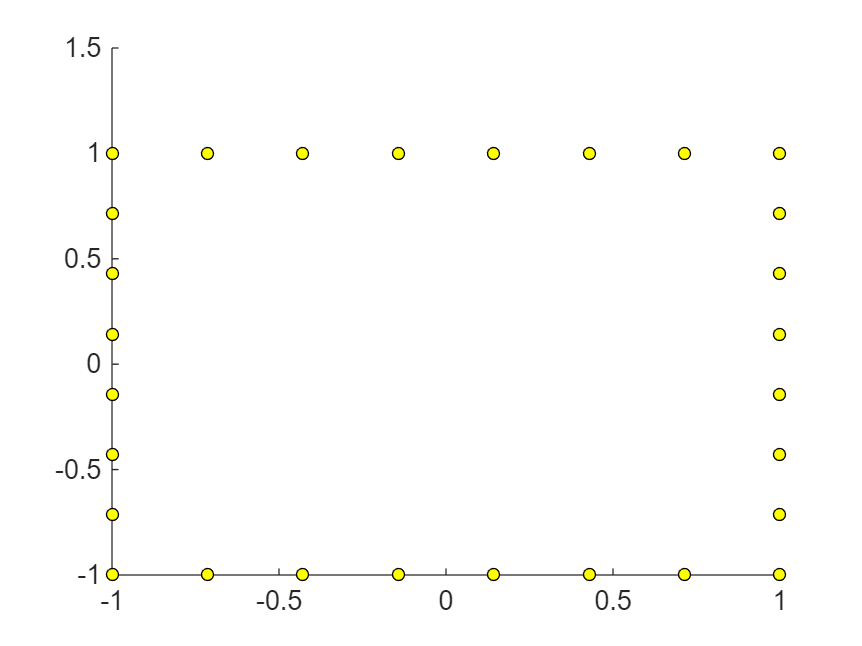

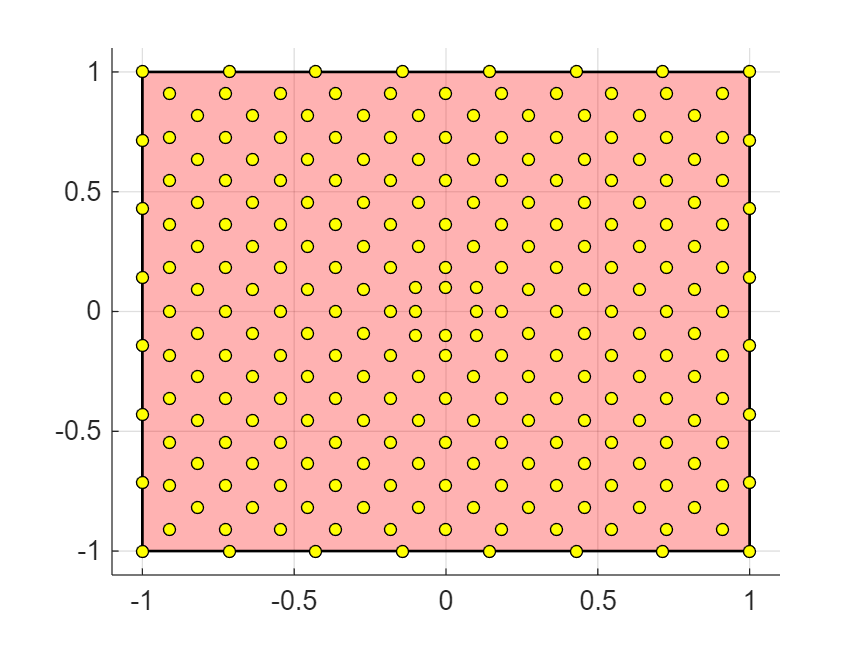

Elapsed time is 1.198668 seconds.
vertices created
 
building the Lyapunov function polyhedron...


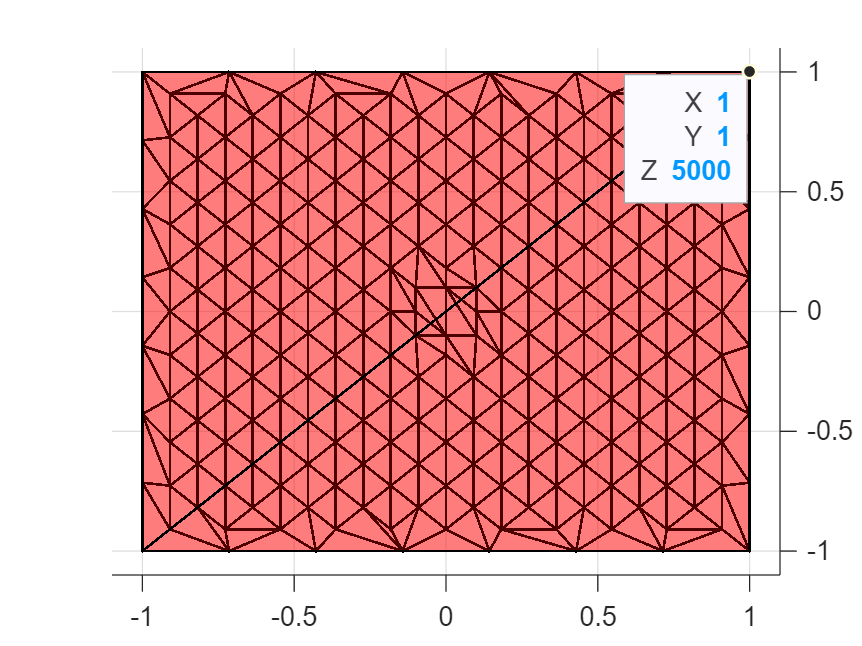

Elapsed time is 5.927190 seconds.
the Lyapunov function polyhedron is built
 
extracting the triangulation...
total loops : 252
5 loops done
10 loops done
15 loops done
20 loops done
25 loops done
30 loops done
35 loops done
40 loops done
45 loops done
50 loops done
55 loops done
60 loops done
65 loops done
70 loops done
75 loops done
80 loops done
85 loops done
90 loops done
95 loops done
100 loops done
105 loops done
110 loops done
115 loops done
120 loops done
125 loops done
130 loops done
135 loops done
140 loops done
145 loops done
150 loops done
155 loops done
160 loops done
165 loops done
170 loops done
175 loops done
180 loops done
185 loops done
190 loops done
195 loops done
200 loops done
205 loops done
210 loops done
215 loops done
220 loops done
225 loops done
230 loops done
235 loops done
240 loops done
245 loops done
250 loops done
Elapsed time is 2322.445375 seconds.
triangulation extracted
 
plotting the resulting polyhedra...
Elapsed time is 60.305068 seconds.
polyhedr

[v,C,Nv,Nc,dX,Tess,extind] = TessellationFinder(Nv,v,C,l_A,'regular');

We plot the resulting tessellation.

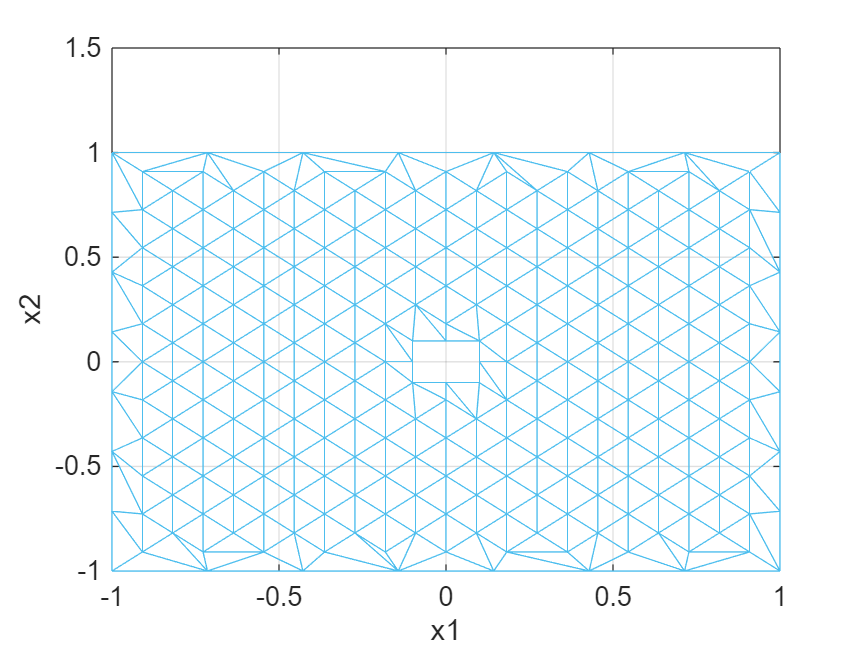

figure
triplot(C, v(1,:), v(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

figure
trisurf(C,v(1,:),v(2,:),zeros(length(v),1),'FaceAlpha',.6)
grid on;

**Step 2 :** generating data.

In this part, we fix the number Nd of datapoints generated initially. The potential dataset is tested to see if it is informative with respect to the tessellation. If it is not, the dataset is regenerated. After a certain number of regenerations and failed tests, the number of datapoints is increased. This goes on until we get a valid dataset, which will then be cleaned of uninformative datapoints.

Nd = 300;
rt = 1.1;
system = 1;
nrm = 2;
M = LC(rt*l(1,2),func(system),nrm);
dtype = 1;
[x,f,Nd] = DataGenerator(Nd,rt*l,v,Tess,system,M,nrm,dtype);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

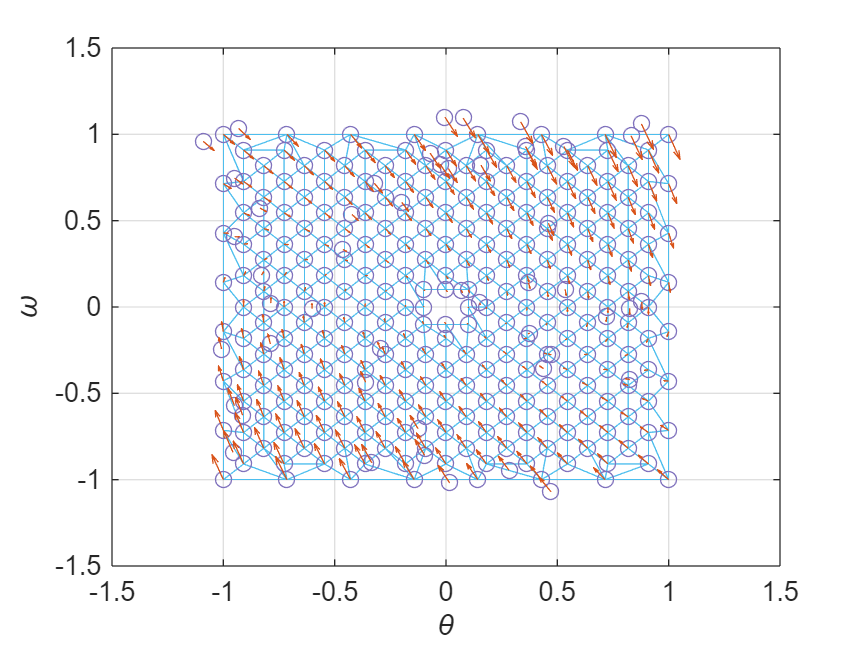

figure
triplot(C, v(1,:), v(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x(1,:), x(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x(1,:), x(2,:), f(1,:), f(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

**Step 3 :** optimisation problem.

In this part, we try to find the piecewise affine Lyapunov function $V$ as described in the introduction through an optimisation problem.

eps = 1e-2; % negativity tolerance
eta = 5; % slack margin
alpha = 200; % upper limit of the Lyapunov function
beta = 0; % lower limit of the Lyapunov function
lim_mode = 0; % additional constraints on function edges wcn
clear gs bs vals ss sum_ss
[gs,bs,vals,ss,sum_ss] = OptimisationProblem(x,f,M,v,C,eps,eta,alpha,beta,dA,dX,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 468
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 6.4115e+04
       solvertime: 48.5216
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 64320.769311 seconds.
optimization ended
 


We plot the solution in 3D.

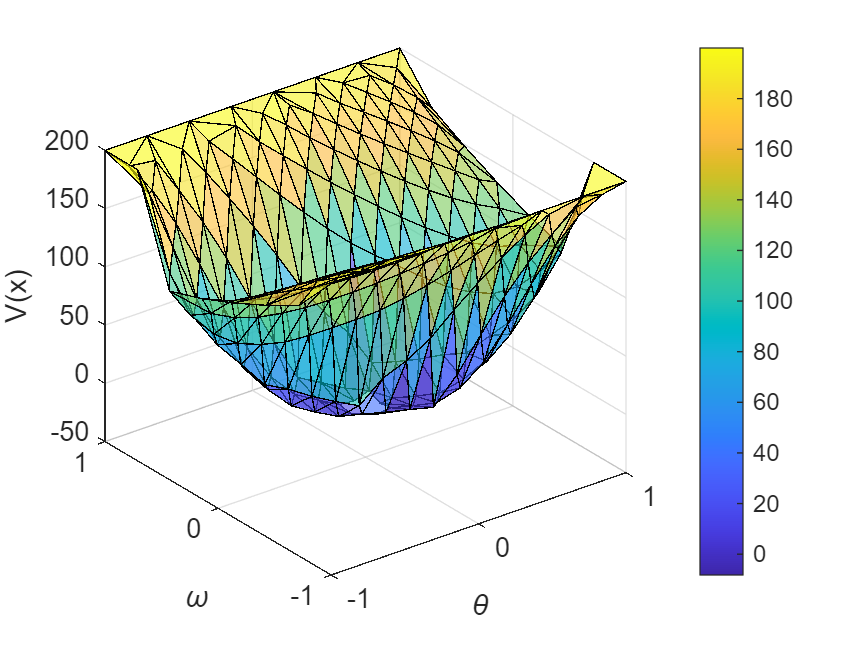

figure
trisurf(C,v(1,:),v(2,:),vals,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

In order to compare the results to the optimal solution, we print the optimal value of the optimisation function :


$$s^*_\eta := \underset{\{s_{i,c}\},\{\gamma_{d,c}\},\{b_c\}}\min \underset{i=1}\overset{3}\Sigma \underset{c=1}\overset{N_c}\Sigma s_{i,c} \ = \ \underset{i=1}\overset{3}\Sigma \underset{c=1}\overset{N_c}\Sigma -\eta \ = \ -3N_c.\eta$$


Then we print the value sum_ss of the optimisation function obtained for our solution, and we print the error between the two values.

fprintf('Computed optimal value : %f\n', -eta*length(C)*3)

Computed optimal value : -7020.000000


fprintf('Obtained optimal value : %f\n', sum_ss)

Obtained optimal value : -6800.625972


fprintf('Error : %f\n', sum_ss + eta*length(C)*3)

Error : 219.374028


**Step 4 :** validating the results.

In the optimisation problem, there is a variable to minimise that is supposed to insure that $\nabla V^Tf$ is negative. It is the slack variable ss, which in the constraint is noted $\{s_{i,c}\}\underset{c=1,...,N_c}\underset{i=1,2,3}
$, and we have $\nabla V^Tf \leq s$.

In this part, we check each slack variable in ss(3,$N_c$) to see if it is negative, and store its indices c and i along with its value in matrix bad_ind(~,3) if it is not.

clear bad_ind bad_triangles bad_points
bad_ind = [];
for c = 1: length(ss)
    for i = 1:3
        if ss(i,c) >= 0
            bad_ind = [bad_ind; [c, i, ss(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

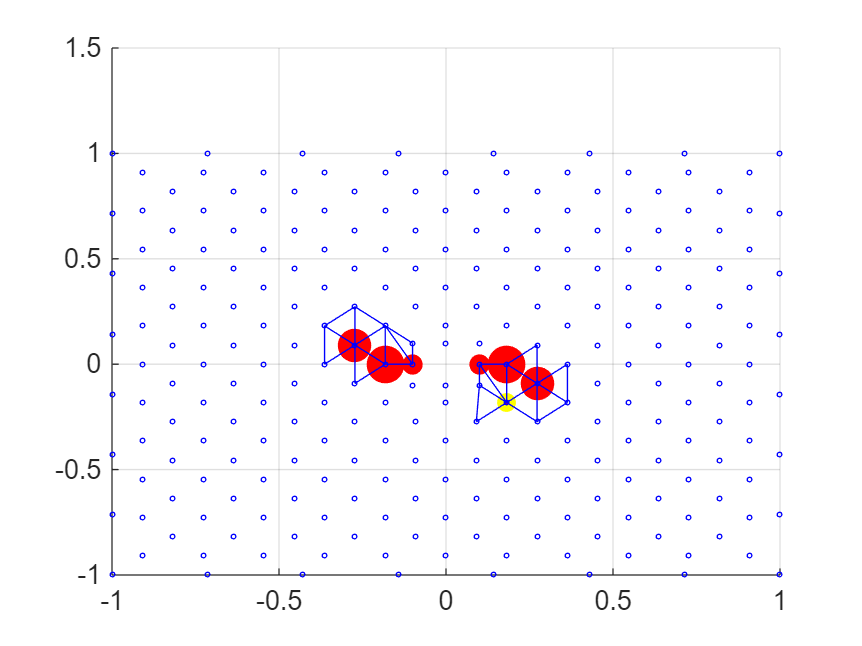

figure
if not(size(bad_ind)==0)
    bad_points = zeros(2, length(bad_ind(:,1)));
    bad_triangles = zeros(length(bad_ind(:,1)), 3);
    for ml = 1:length(bad_ind(:,1))
        bad_points(:,ml) = [v(1,C(bad_ind(ml,1),bad_ind(ml,2))); v(2,C(bad_ind(ml,1),bad_ind(ml,2)))]; % points' coordinates
        bad_triangles(ml,:) = C(bad_ind(ml,1),:); % triangles' indices
    end
    scatter(bad_points(1,:), bad_points(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points(1,:), bad_points(2,:), bad_ind(:,3).*200./max(bad_ind(:,3)), 'r', 'filled')
    triplot(bad_triangles, v(1,:), v(2,:))
end
scatter(v(1,:), v(2,:), 3, 'b')
grid on

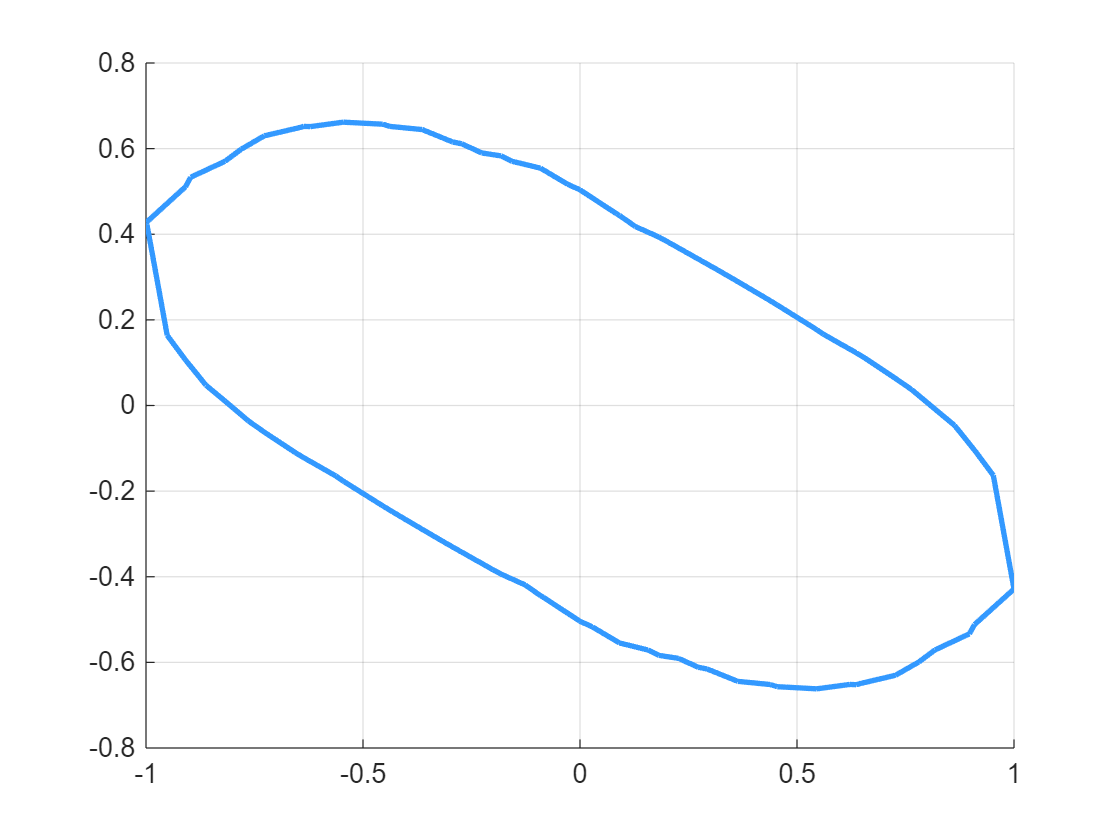

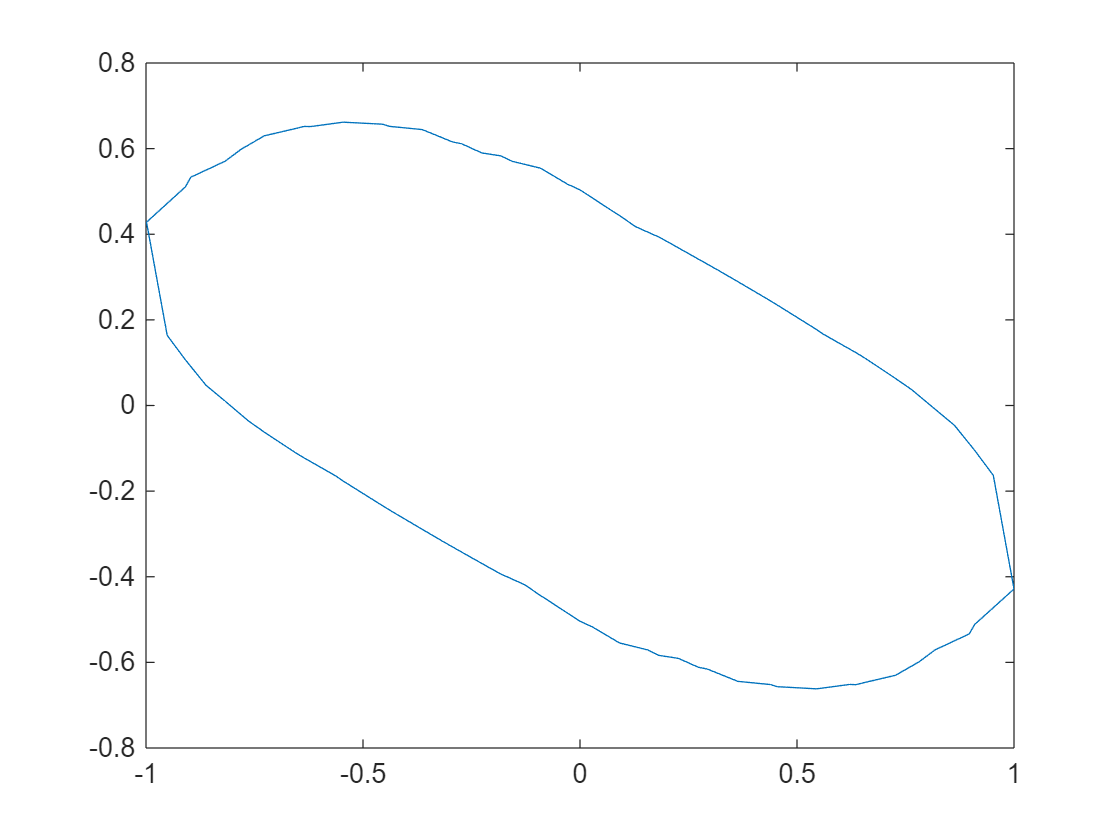

pointlist =     0.4391   -0.6518
    0.3636   -0.6443
    0.2934   -0.6157
    0.2727   -0.6115
    0.2270   -0.5907
    0.1818   -0.5837
    0.1563   -0.5710
    0.0909   -0.5546
    0.0284   -0.5171
         0   -0.5040


[pointlist,a] = sublevelset(dX,C,v,gs,bs,vals,1,[.2 .6 1])

creating new vertices... 


k = 1.0200

k = 1.0400

k = 1.0600

k = 1.0800

k = 1.1000

k = 1.1200

k = 1.1400

k = 1.1600

k = 1.1800

k = 1.2000

k = 1.2200

k = 1.2400

k = 1.2600

k = 1.2800

k = 1.3000

k = 1.3200

k = 1.3400

k = 1.3600

k = 1.3800

k = 1.4000

k = 1.4200

k = 1.4400

k = 1.4600

k = 1.4800

k = 1.5000

k = 1.5200

k = 1.5400

k = 1.5600

k = 1.5800

k = 1.6000

k = 1.6200

k = 1.6400

k = 1.6600

k = 1.6800

k = 1.7000

k = 1.7200

k = 1.7400

k = 1.7600

k = 1.7800

k = 1.8000

k = 1.8200

k = 1.8400

k = 1.8600

k = 1.8800

k = 1.9000

k = 1.9200

k = 1.9400

k = 1.9600

k = 1.9800

k = 2.0000

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

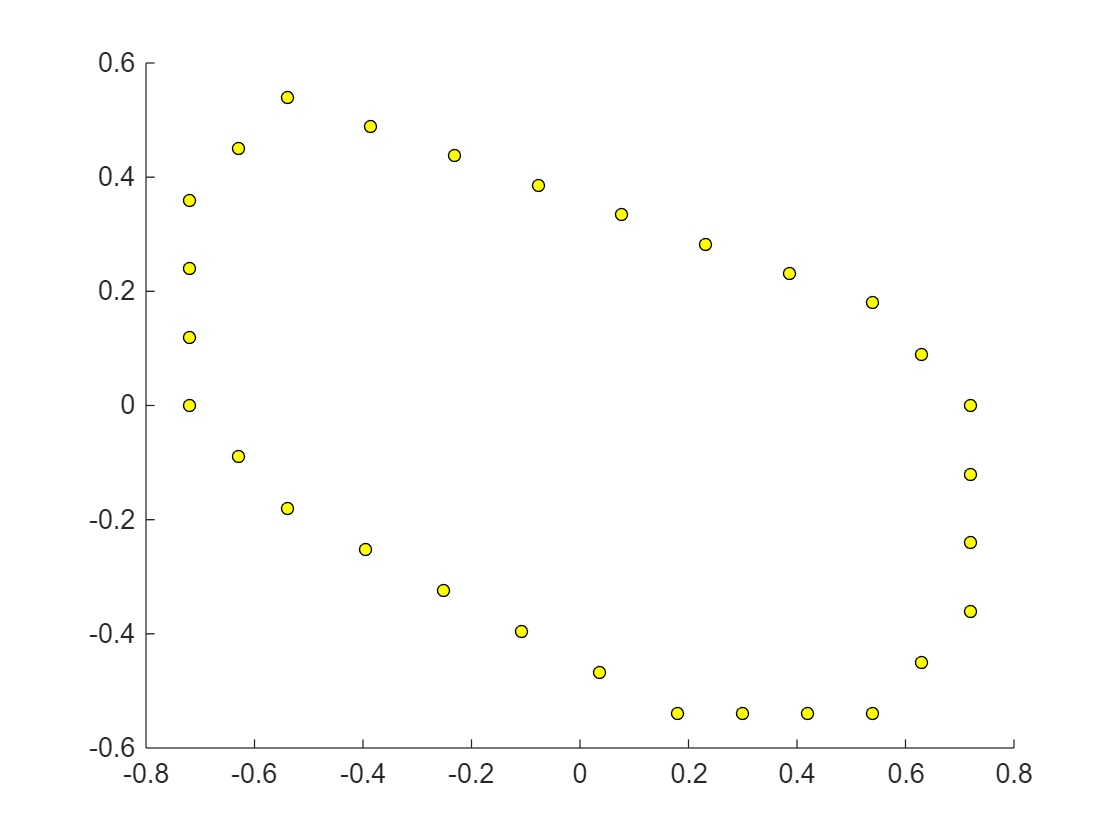

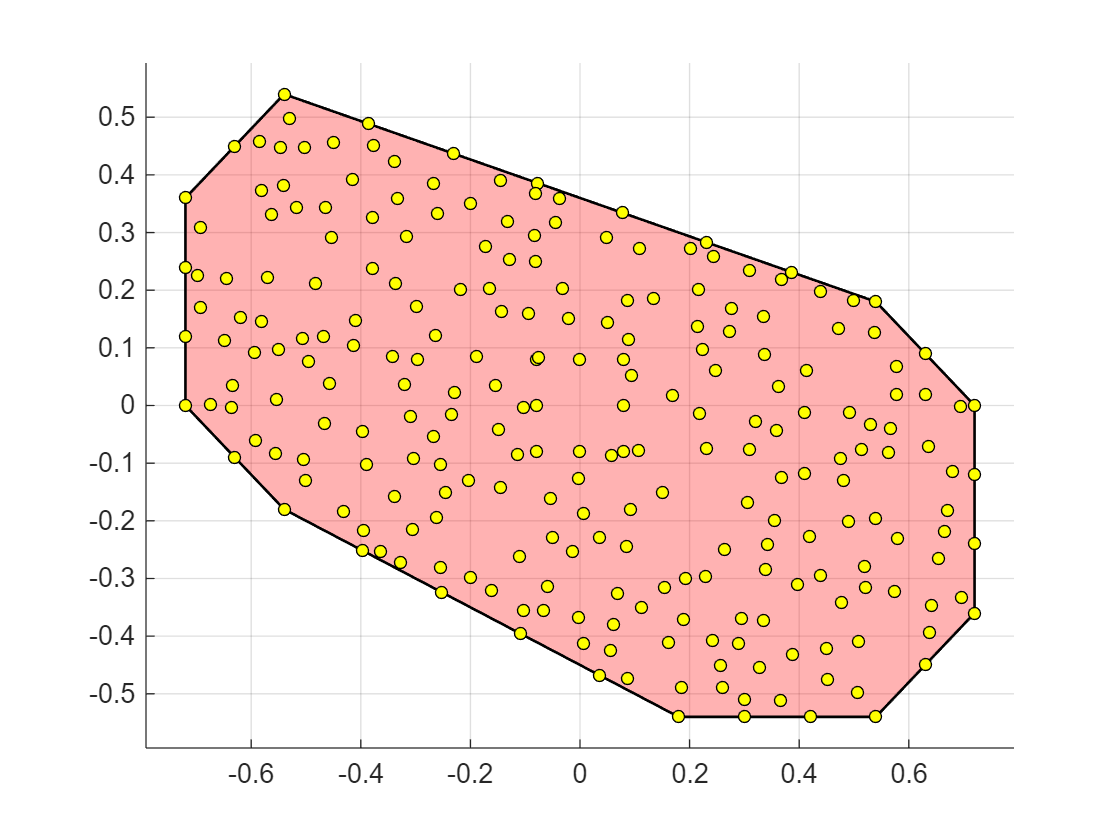

Elapsed time is 0.066167 seconds.
vertices created
 
Elapsed time is 0.068954 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 2.176222 seconds.
tessellation cleaning ended
 


Output argument "extind" (and possibly others) not assigned a value in the execution with "TessellationFinderV3" function.

clear v_new C_new Tess_new
[v_new,C_new,Nv_new,Nc_new,dX_new,Tess_new,extind_new] = TessellationFinderV2(250,v,bad_triangles,0.8*l_A,'random',pointlist,0.025);

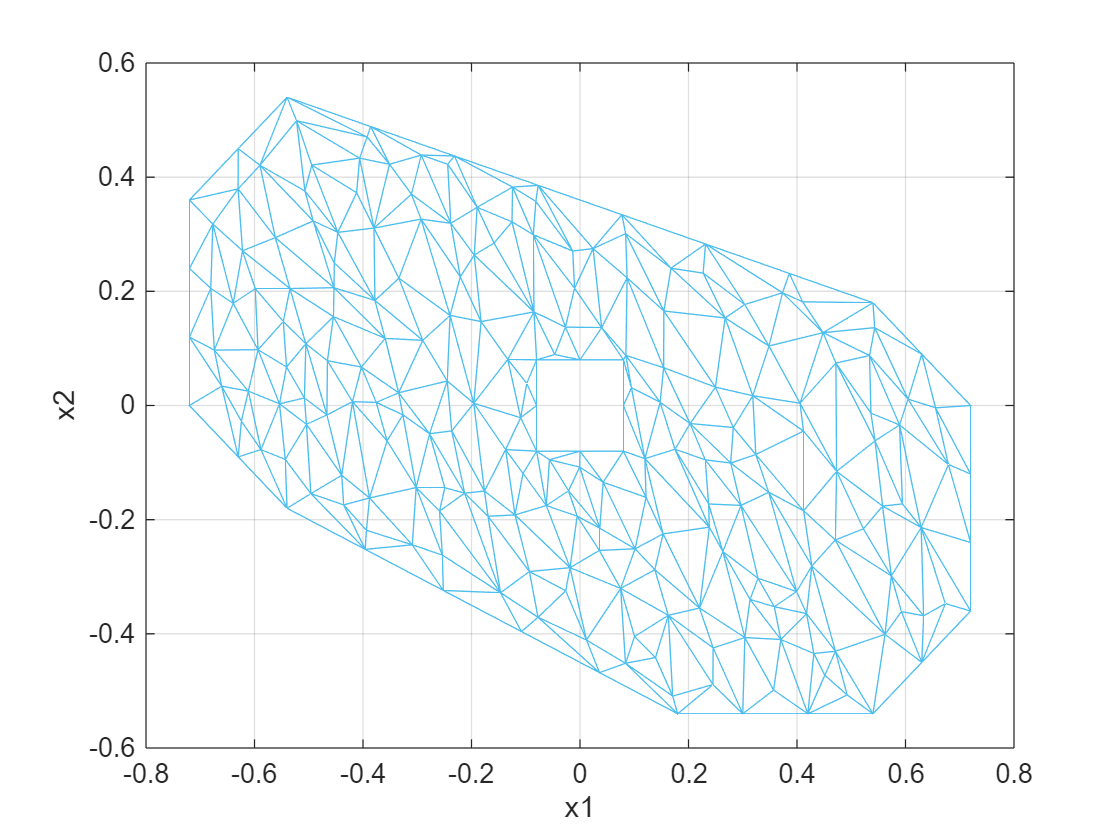

figure
triplot(C_new, v_new(1,:), v_new(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

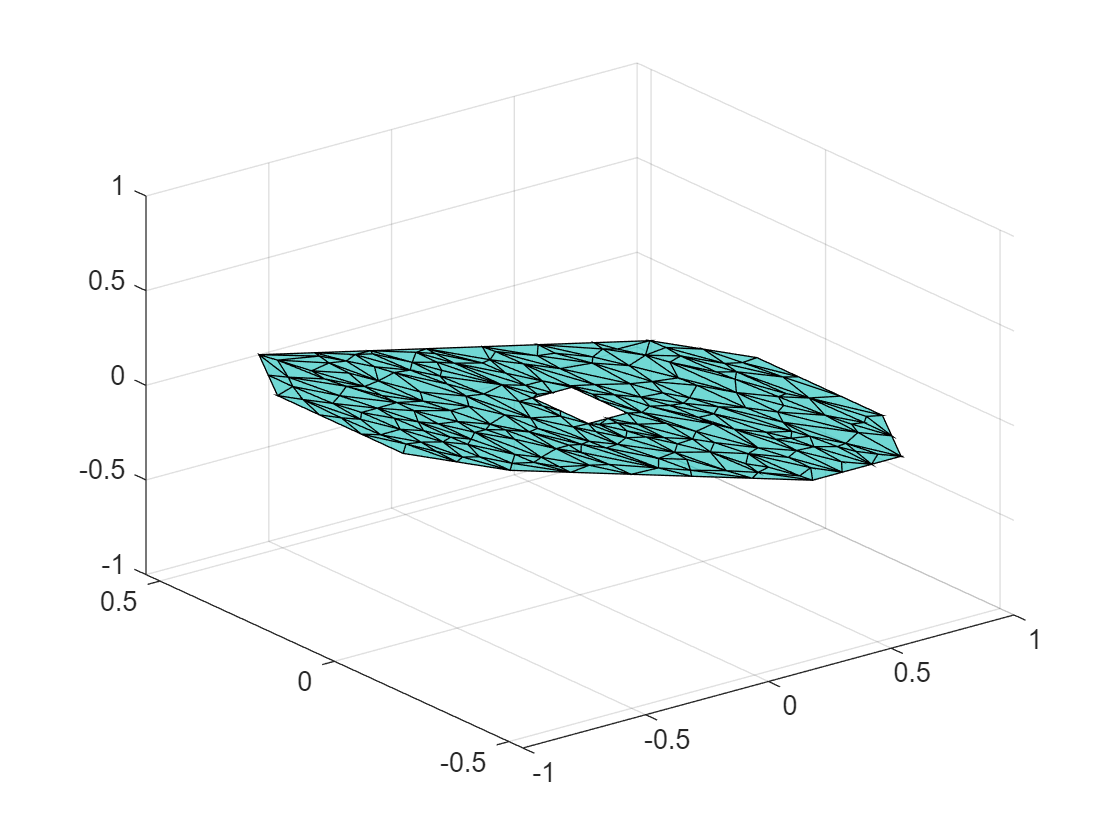

figure
trisurf(C_new,v_new(1,:),v_new(2,:),zeros(length(v_new),1),'FaceAlpha',.6)
grid on

l_new = [min(v_new(1,:)),max(v_new(1,:));min(v_new(2,:)),max(v_new(2,:))];
[x_new,f_new,Nd_new] = DataGenerator(350,rt,l_new,v_new,Tess_new,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

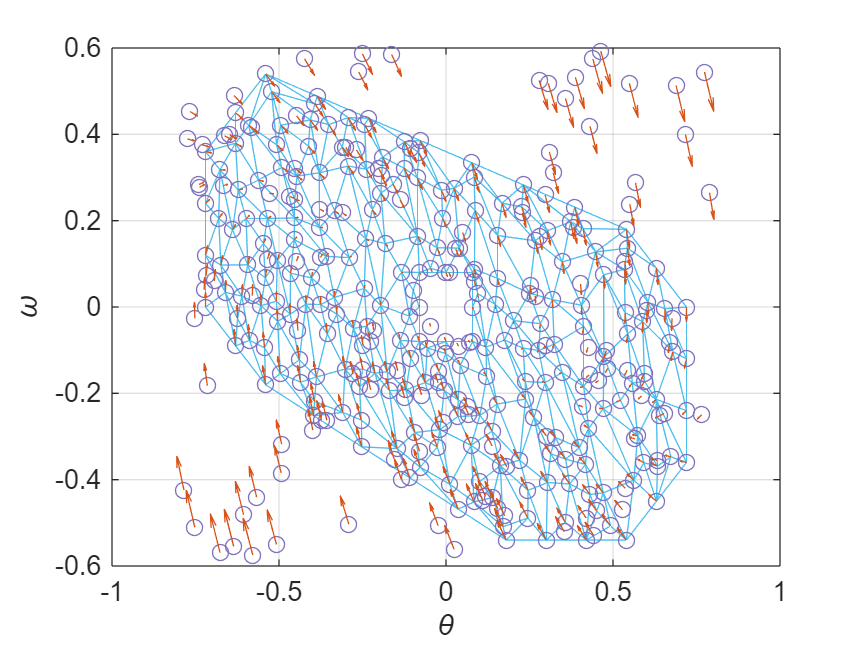

figure
triplot(C_new, v_new(1,:), v_new(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new(1,:), x_new(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new(1,:), x_new(2,:), f_new(1,:), f_new(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new bs_new vals_new ss_new sum_ss_new
[gs_new,bs_new,vals_new,ss_new,sum_ss_new] = OptimisationProblem(x_new,f_new,M,v_new,C_new,eps,eta,alpha,beta,dA,dX_new,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 407
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 2.6398e+03
       solvertime: 55.8434
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 2810.173603 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new)*3)

Computed optimal value : -6105.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new)

Obtained optimal value : -5844.425525


fprintf('Error : %f\n', sum_ss_new + eta*length(C_new)*3)

Error : 260.574475


We plot the solution in 3D, each triangle is plotted independently from the others.

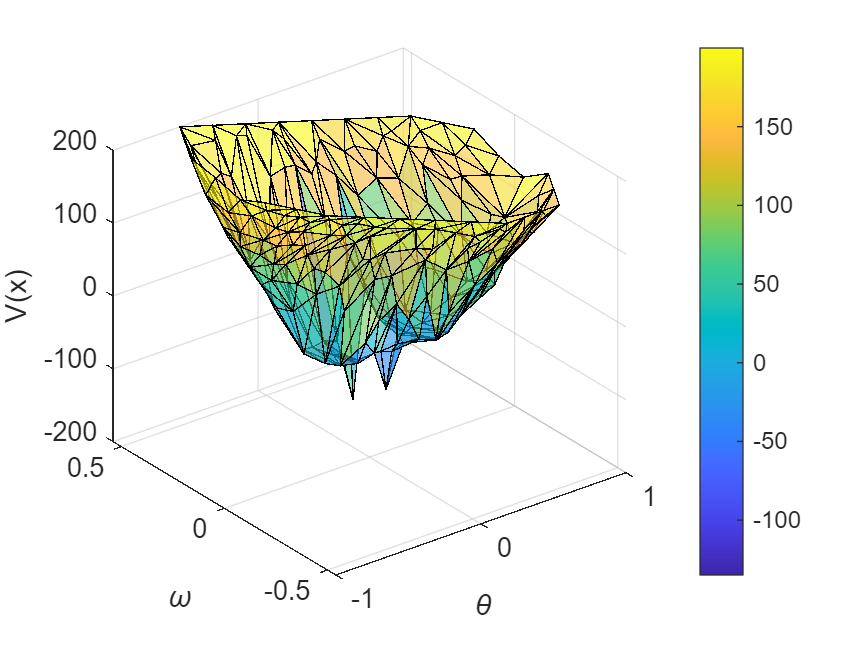

figure
trisurf(C_new,v_new(1,:),v_new(2,:),vals_new,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new bad_triangles_new bad_points_new
bad_ind_new = [];
for c = 1: length(ss_new)
    for i = 1:3
        if ss_new(i,c) >= 0
            bad_ind_new = [bad_ind_new; [c, i, ss_new(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

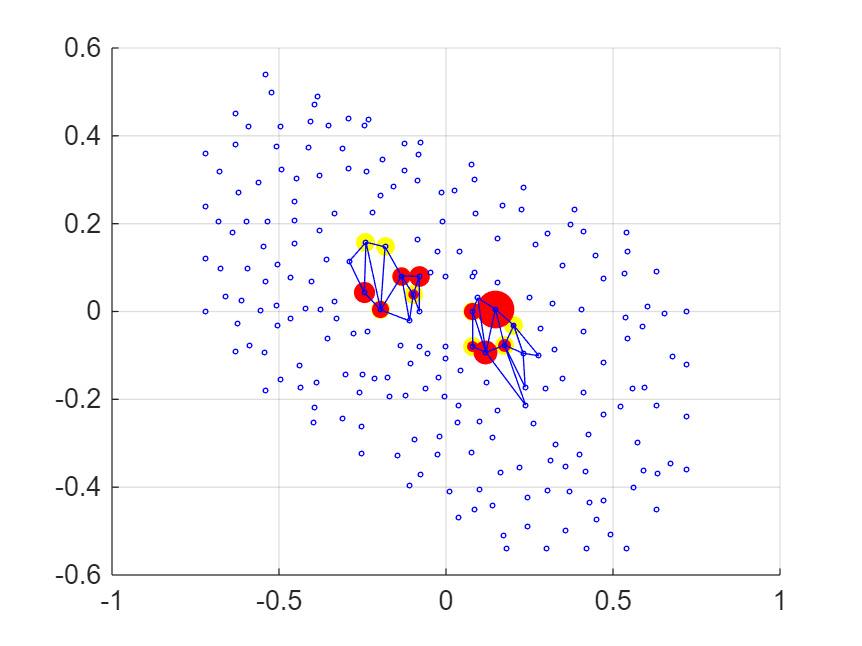

figure
if not(size(bad_ind_new)==0)
    bad_points_new = zeros(2, length(bad_ind_new(:,1)));
    bad_triangles_new = zeros(length(bad_ind_new(:,1)), 3);
    for ml = 1:length(bad_ind_new(:,1))
        bad_points_new(:,ml) = [v_new(1,C_new(bad_ind_new(ml,1),bad_ind_new(ml,2))); v_new(2,C_new(bad_ind_new(ml,1),bad_ind_new(ml,2)))]; % points' coordinates
        bad_triangles_new(ml,:) = C_new(bad_ind_new(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new(1,:), bad_points_new(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new(1,:), bad_points_new(2,:), bad_ind_new(:,3).*200./max(bad_ind_new(:,3)), 'r', 'filled')
    triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
end
scatter(v_new(1,:), v_new(2,:), 3, 'b')
grid on

[pointlist_new,a_new] = sublevelset(dX_new,C_new,v_new,gs_new,bs_new,vals_new,1,[.2 .6 1])

pointlist_new =    -0.7098    0.1421
   -0.7033    0.2253
   -0.7007    0.1104
   -0.6996    0.2768
   -0.6965    0.3371
   -0.6643    0.0518
   -0.6641    0.3721
   -0.6513    0.0323
   -0.6301    0.4060
   -0.6216   -0.0168


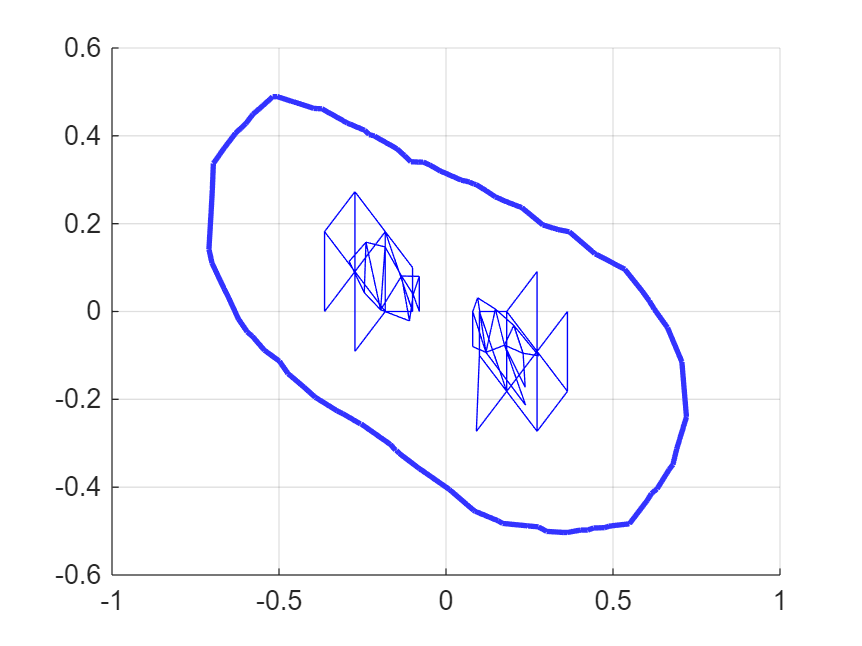

triplot(bad_triangles, v(1,:), v(2,:))
triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
grid on

creating new vertices... 


k = 1.0200

k = 1.0400

k = 1.0600

k = 1.0800

k = 1.1000

k = 1.1200

k = 1.1400

k = 1.1600

k = 1.1800

k = 1.2000

k = 1.2200

k = 1.2400

k = 1.2600

k = 1.2800

k = 1.3000

k = 1.3200

k = 1.3400

k = 1.3600

k = 1.3800

k = 1.4000

k = 1.4200

k = 1.4400

k = 1.4600

k = 1.4800

k = 1.5000

k = 1.5200

k = 1.5400

k = 1.5600

k = 1.5800

k = 1.6000

k = 1.6200

k = 1.6400

k = 1.6600

k = 1.6800

k = 1.7000

k = 1.7200

k = 1.7400

k = 1.7600

k = 1.7800

k = 1.8000

k = 1.8200

k = 1.8400

k = 1.8600

k = 1.8800

k = 1.9000

k = 1.9200

k = 1.9400

k = 1.9600

k = 1.9800

k = 2.0000

k = 2.0200

k = 2.0400

k = 2.0600

k = 2.0800

k = 2.1000

k = 2.1200

k = 2.1400

k = 2.1600

k = 2.1800

k = 2.2000

k = 2.2200

k = 2.2400

k = 2.2600

k = 2.2800

k = 2.3000

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

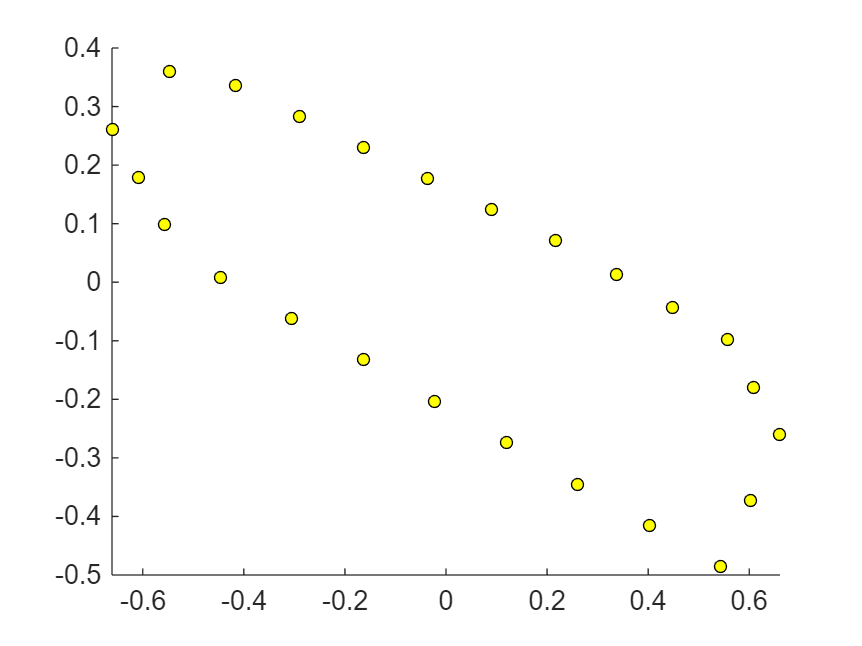

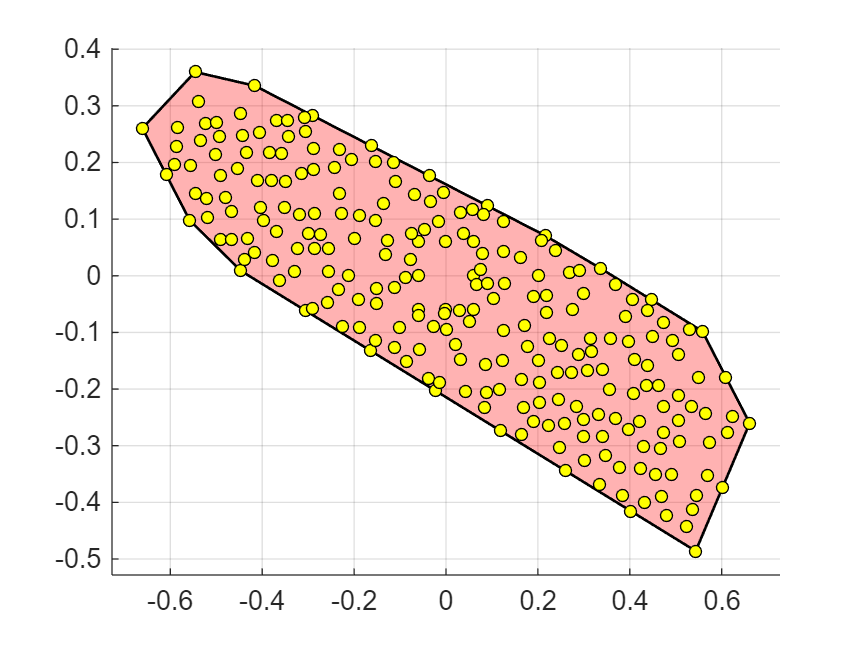

Elapsed time is 0.115100 seconds.
vertices created
 
building the Lyapunov function polyhedron...


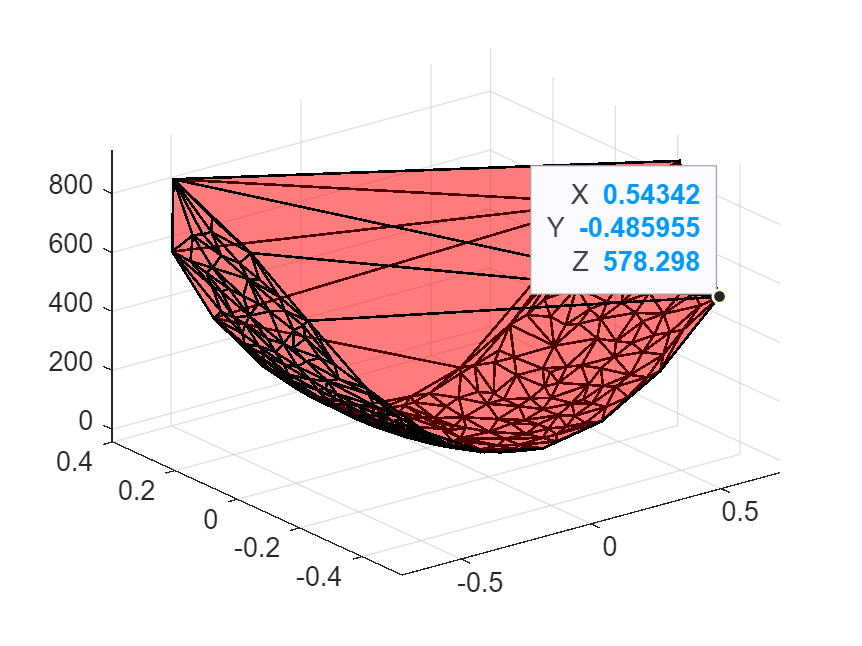

Elapsed time is 3.686641 seconds.
the Lyapunov function polyhedron is built
 
extracting the triangulation...
total loops : 238
5 loops done
10 loops done
15 loops done
20 loops done
25 loops done
30 loops done
35 loops done
40 loops done
45 loops done
50 loops done
55 loops done
60 loops done
65 loops done
70 loops done
75 loops done
80 loops done
85 loops done
90 loops done
95 loops done
100 loops done
105 loops done
110 loops done
115 loops done
120 loops done
125 loops done
130 loops done
135 loops done
140 loops done
145 loops done
150 loops done
155 loops done
160 loops done
165 loops done
170 loops done
175 loops done
180 loops done
185 loops done
190 loops done
195 loops done
200 loops done
205 loops done
210 loops done
215 loops done
220 loops done
225 loops done
230 loops done
235 loops done
Elapsed time is 1538.999742 seconds.
triangulation extracted
 
plotting the resulting polyhedra...
Elapsed time is 47.574003 seconds.
polyhedra construction and plot ended
 
cleaning the 

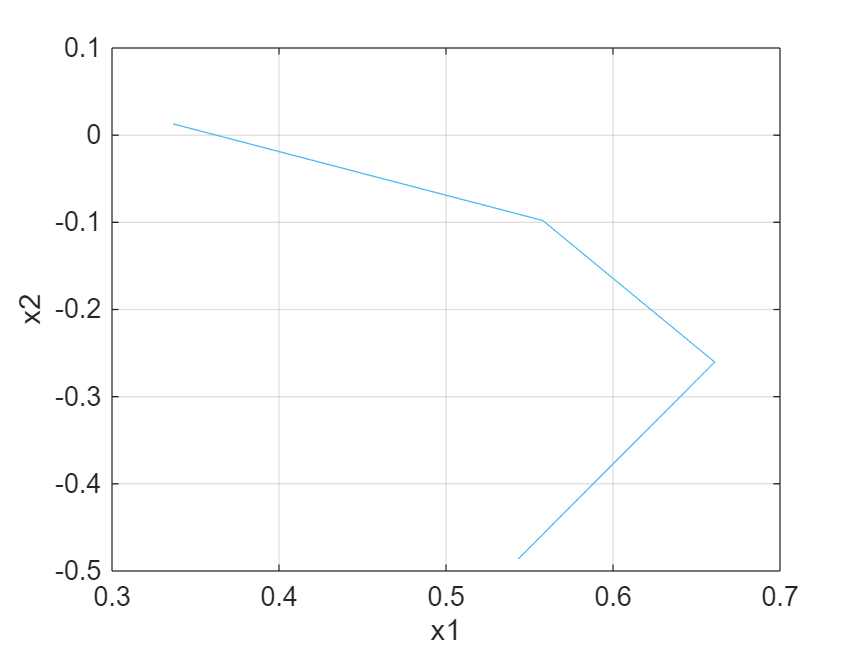

Elapsed time is 0.210694 seconds.
constraint verification ended
 


[v_new1,C_new1,Nv_new1,Nc_new1,dX_new1,Tess_new1,extind_new1] = TessellationFinderV2(250,v_new,bad_triangles_new,0.6*l_A,'random',pointlist_new,0.017);

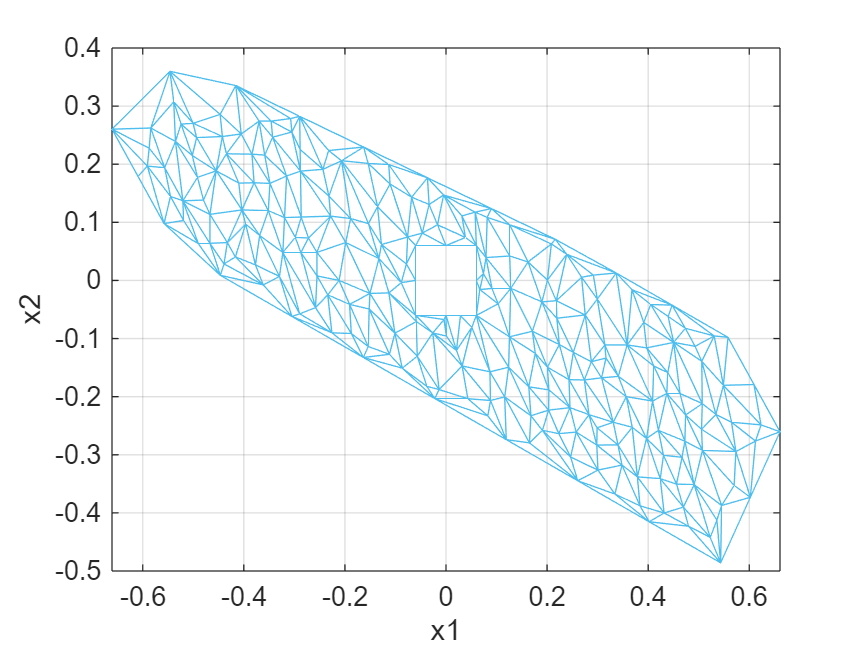

figure
triplot(C_new1, v_new1(1,:), v_new1(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

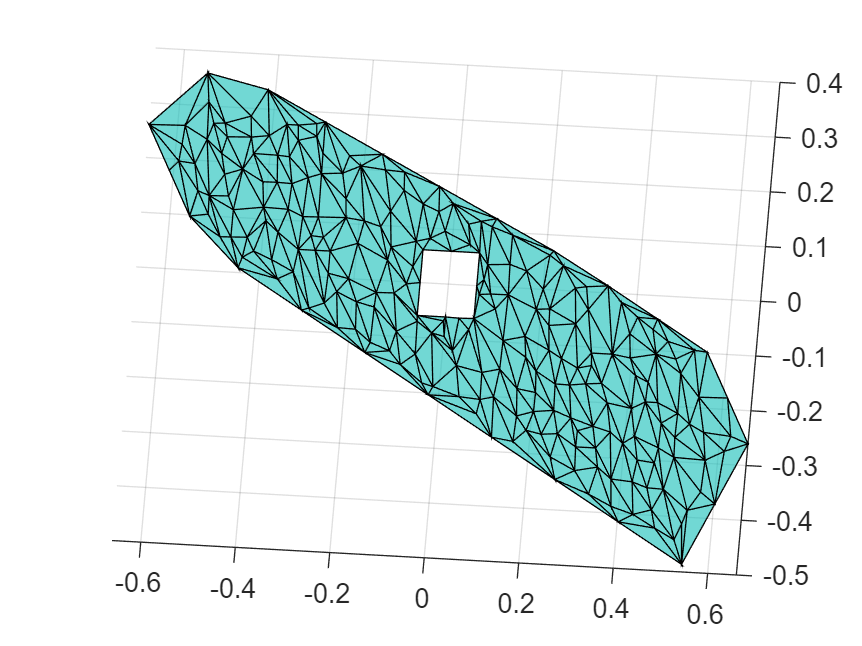

figure
trisurf(C_new1,v_new1(1,:),v_new1(2,:),zeros(length(v_new1),1),'FaceAlpha',.6)
grid on

l_new1 = [min(v_new1(1,:)),max(v_new1(1,:));min(v_new1(2,:)),max(v_new1(2,:))];
[x_new1,f_new1,Nd_new1] = DataGenerator(350,rt,l_new1,v_new1,Tess_new1,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

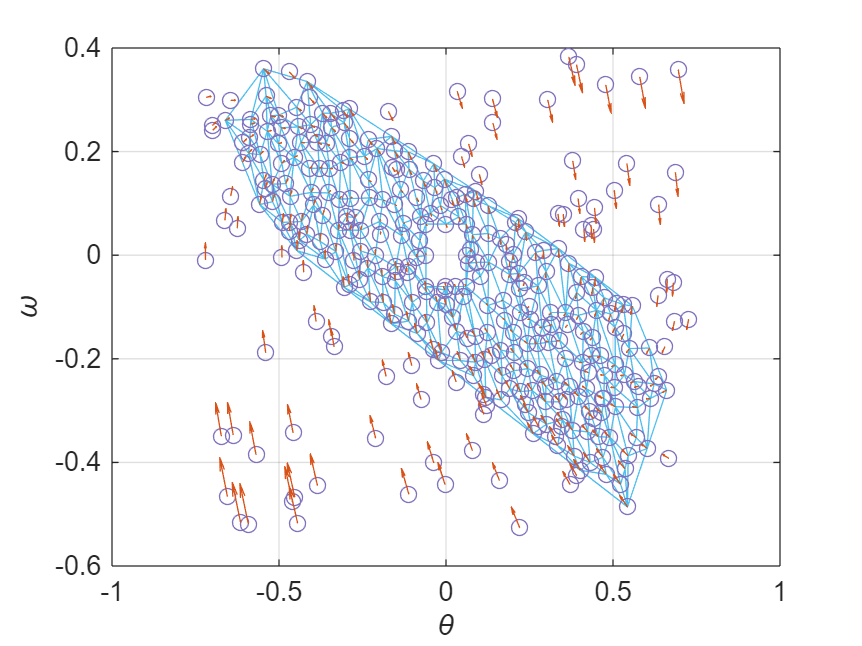

figure
triplot(C_new1, v_new1(1,:), v_new1(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new1(1,:), x_new1(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new1(1,:), x_new1(2,:), f_new1(1,:), f_new1(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new1 bs_new1 vals_new1 ss_new1 sum_ss_new1
[gs_new1,bs_new1,vals_new1,ss_new1,sum_ss_new1] = OptimisationProblem(x_new1,f_new1,M,v_new1,C_new1,eps,eta,alpha,beta,dA,dX_new1,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 443
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 3.2115e+03
       solvertime: 93.0744
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 3455.046391 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new1)*3)

Computed optimal value : -6645.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new1)

Obtained optimal value : -6419.631792


fprintf('Error : %f\n', sum_ss_new1 + eta*length(C_new1)*3)

Error : 225.368208


We plot the solution in 3D, each triangle is plotted independently from the others.

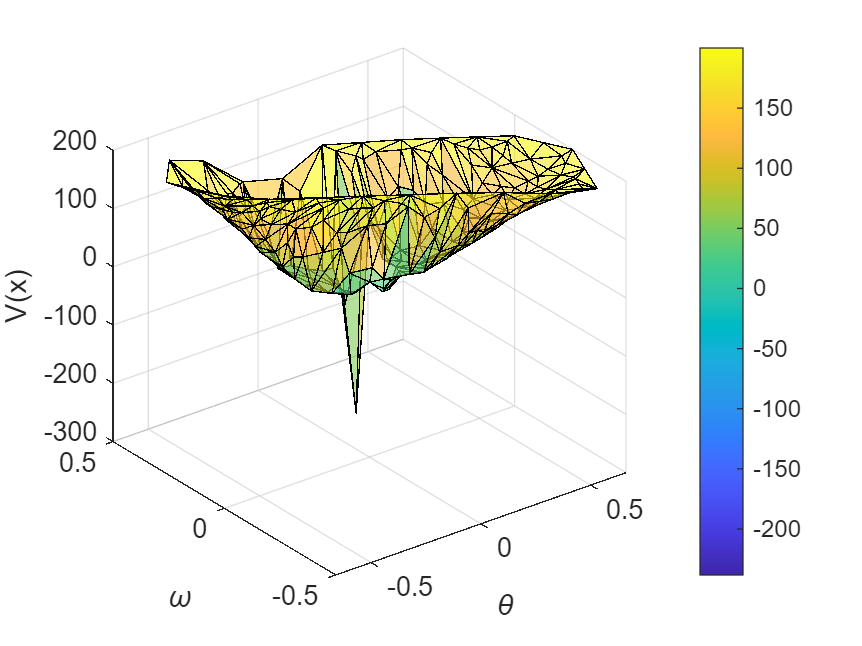

figure
trisurf(C_new1,v_new1(1,:),v_new1(2,:),vals_new1,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new1 bad_triangles_new1 bad_points_new1
bad_ind_new1 = [];
for c = 1:length(ss_new1)
    for i = 1:3
        if ss_new1(i,c) >= 0
            bad_ind_new1 = [bad_ind_new1; [c, i, ss_new1(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

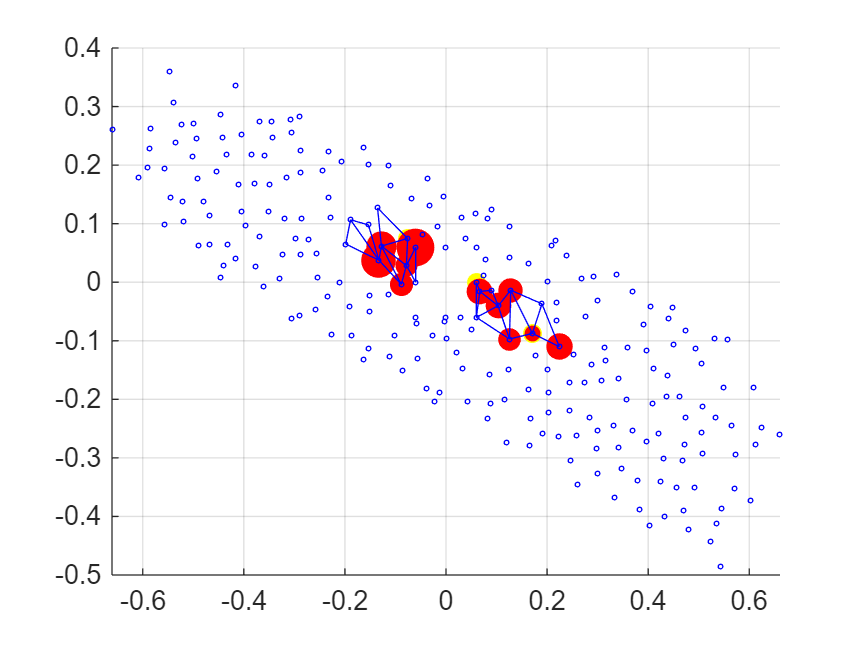

figure
if not(size(bad_ind_new1)==0)
    bad_points_new1 = zeros(2, length(bad_ind_new1(:,1)));
    bad_triangles_new1 = zeros(length(bad_ind_new1(:,1)), 3);
    for ml = 1:length(bad_ind_new1(:,1))
        bad_points_new1(:,ml) = [v_new1(1,C_new1(bad_ind_new1(ml,1),bad_ind_new1(ml,2))); v_new1(2,C_new1(bad_ind_new1(ml,1),bad_ind_new1(ml,2)))]; % points' coordinates
        bad_triangles_new1(ml,:) = C_new1(bad_ind_new1(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new1(1,:), bad_points_new1(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new1(1,:), bad_points_new1(2,:), bad_ind_new1(:,3).*200./max(bad_ind_new1(:,3)), 'r', 'filled')
    triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
end
scatter(v_new1(1,:), v_new1(2,:), 3, 'b')
grid on

[pointlist_new1,a_new1] = sublevelset(dX_new1,C_new1,v_new1,gs_new1,bs_new1,vals_new1,1,[.2 .6 1])

pointlist_new1 =    -0.4992    0.2134
   -0.4982    0.2286
   -0.4961    0.2477
   -0.4949    0.2507
   -0.4860    0.1792
   -0.4833    0.2638
   -0.4739    0.1502
   -0.4630    0.1384
   -0.4476    0.1161
   -0.4458    0.2757


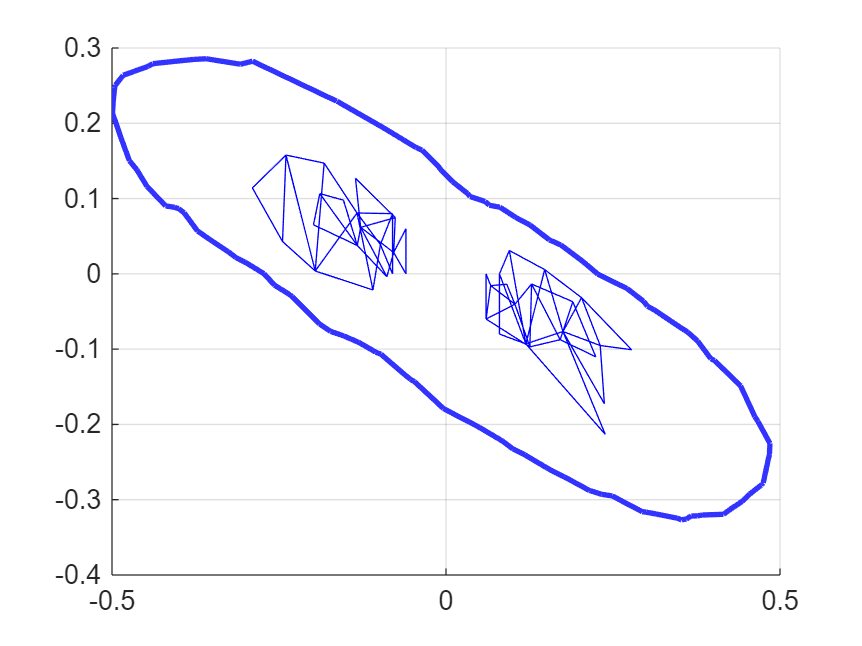

triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
grid on

creating new vertices... 


k = 1.0200

k = 1.0400

k = 1.0600

k = 1.0800

k = 1.1000

k = 1.1200

k = 1.1400

k = 1.1600

k = 1.1800

k = 1.2000

k = 1.2200

k = 1.2400

k = 1.2600

k = 1.2800

k = 1.3000

k = 1.3200

k = 1.3400

k = 1.3600

k = 1.3800

k = 1.4000

k = 1.4200

k = 1.4400

k = 1.4600

k = 1.4800

k = 1.5000

k = 1.5200

k = 1.5400

k = 1.5600

k = 1.5800

k = 1.6000

k = 1.6200

k = 1.6400

k = 1.6600

k = 1.6800

k = 1.7000

k = 1.7200

k = 1.7400

k = 1.7600

k = 1.7800

k = 1.8000

k = 1.8200

k = 1.8400

k = 1.8600

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

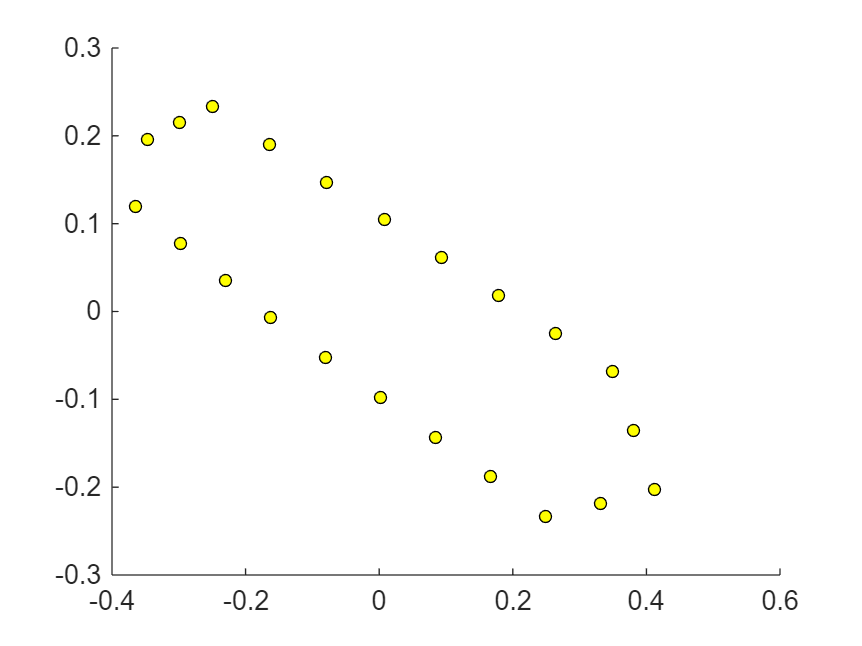

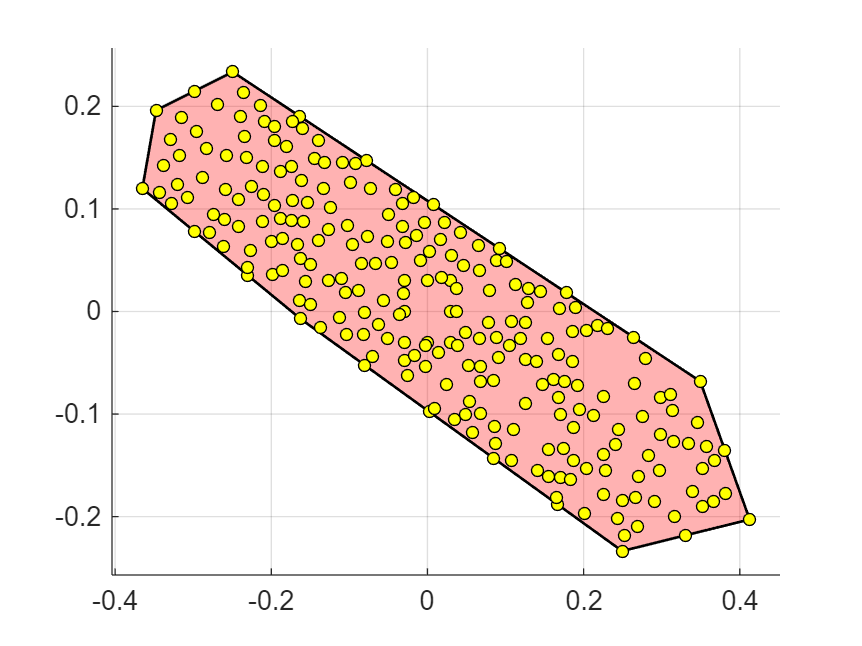

Elapsed time is 0.110429 seconds.
vertices created
 
building the Lyapunov function polyhedron...


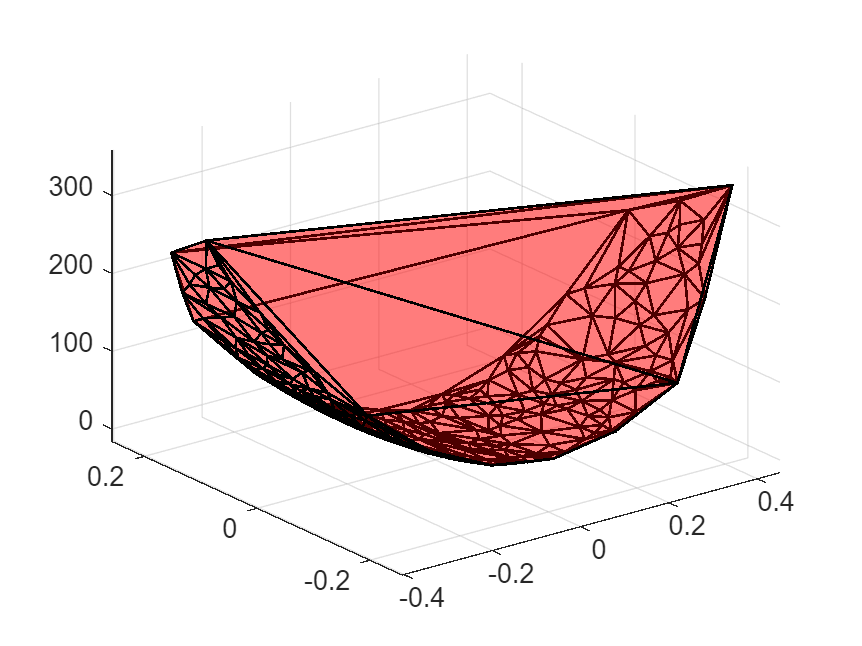

Elapsed time is 3.848868 seconds.
the Lyapunov function polyhedron is built
 
extracting the triangulation...
total loops : 241
5 loops done
10 loops done
15 loops done
20 loops done
25 loops done
30 loops done
35 loops done
40 loops done
45 loops done
50 loops done
55 loops done
60 loops done
65 loops done
70 loops done
75 loops done
80 loops done
85 loops done
90 loops done
95 loops done
100 loops done
105 loops done
110 loops done
115 loops done
120 loops done
125 loops done
130 loops done
135 loops done
140 loops done
145 loops done
150 loops done
155 loops done
160 loops done
165 loops done
170 loops done
175 loops done
180 loops done
185 loops done
190 loops done
195 loops done
200 loops done
205 loops done
210 loops done
215 loops done
220 loops done
225 loops done
230 loops done
235 loops done
240 loops done
Elapsed time is 2002.208595 seconds.
triangulation extracted
 
plotting the resulting polyhedra...
Elapsed time is 47.873724 seconds.
polyhedra construction and plot ended


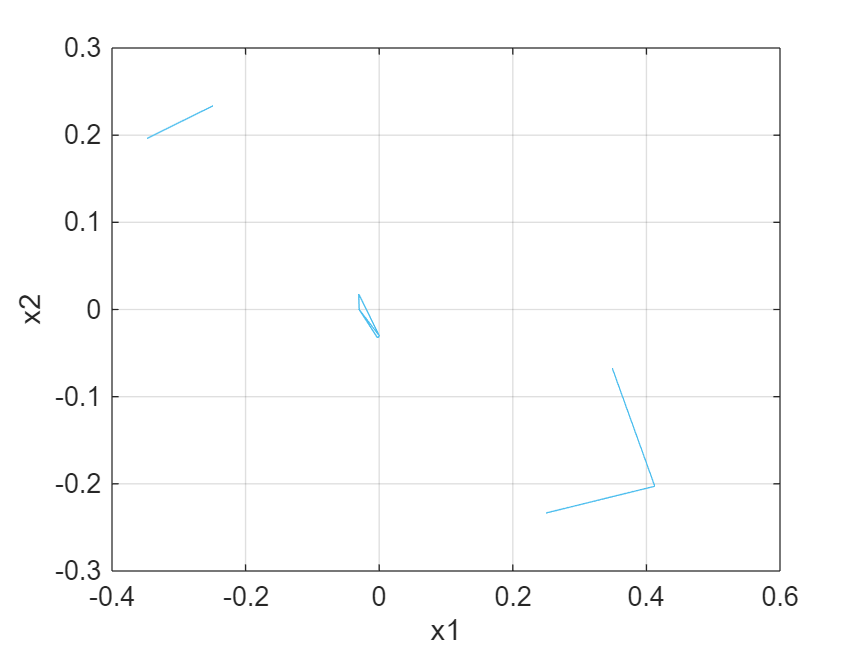

Elapsed time is 0.077736 seconds.
constraint verification ended
 


[v_new2,C_new2,Nv_new2,Nc_new2,dX_new2,Tess_new2,extind_new2] = TessellationFinderV2(250,v_new1,bad_triangles_new1,0.3*l_A,'random',pointlist_new1,0.015);

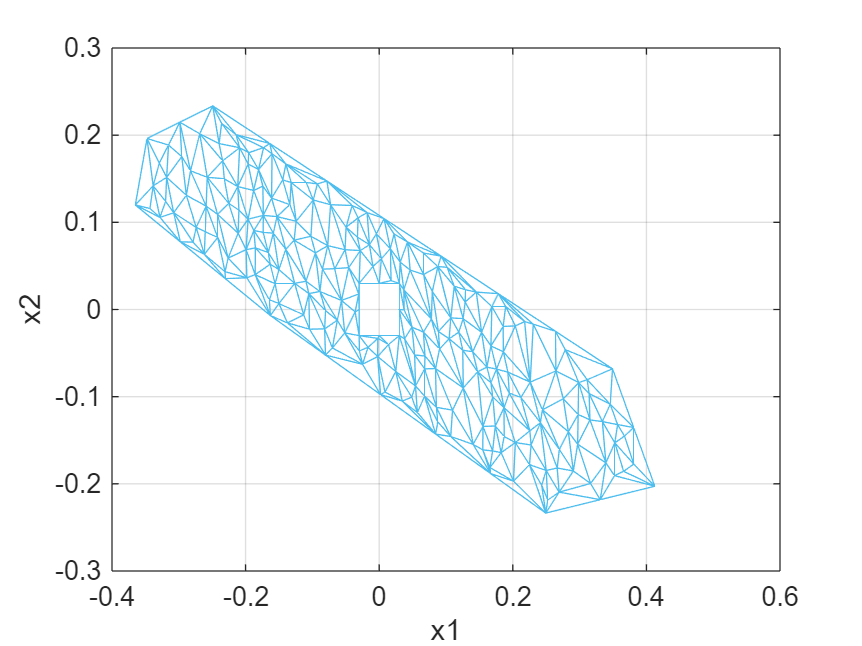

figure
triplot(C_new2, v_new2(1,:), v_new2(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

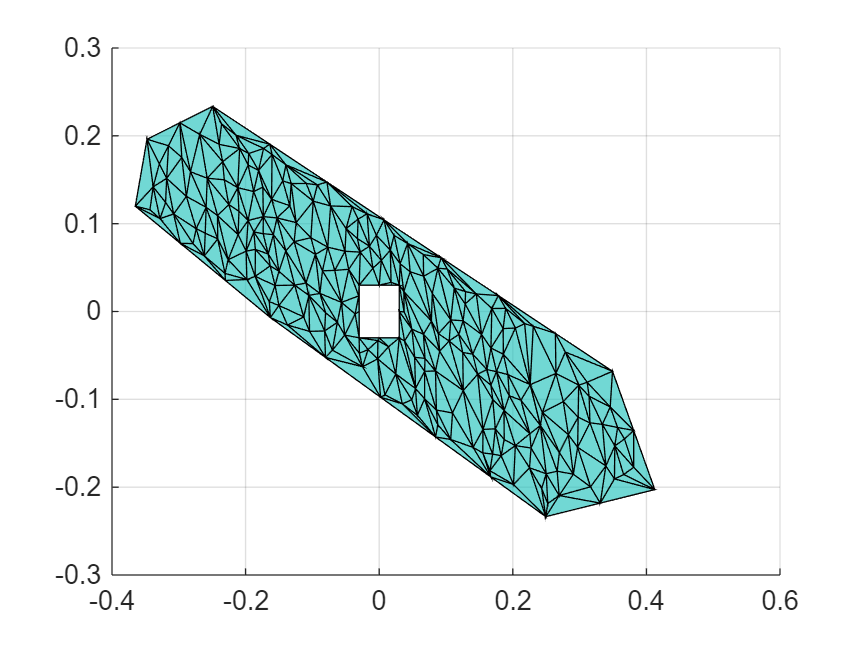

figure
trisurf(C_new2,v_new2(1,:),v_new2(2,:),zeros(length(v_new2),1),'FaceAlpha',.6)
grid on

l_new2 = [min(v_new2(1,:)),max(v_new2(1,:));min(v_new2(2,:)),max(v_new2(2,:))];
[x_new2,f_new2,Nd_new2] = DataGenerator(350,rt,l_new2,v_new2,Tess_new2,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

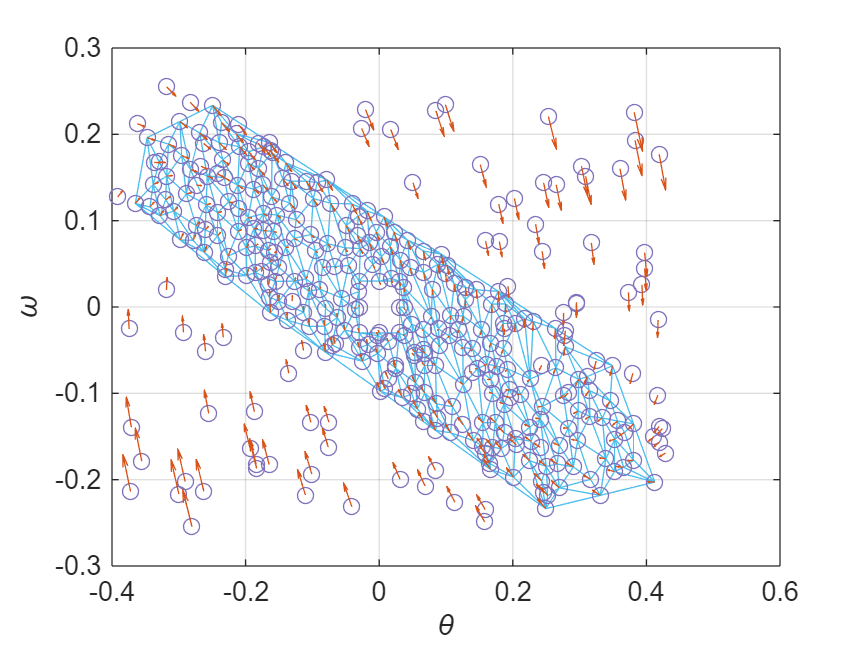

figure
triplot(C_new2, v_new2(1,:), v_new2(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new2(1,:), x_new2(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new2(1,:), x_new2(2,:), f_new2(1,:), f_new2(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new2 bs_new2 vals_new2 ss_new2 sum_ss_new2
[gs_new2,bs_new2,vals_new2,ss_new2,sum_ss_new2] = OptimisationProblem(x_new2,f_new2,M,v_new2,C_new2,eps,eta,alpha,beta,dA,dX_new2,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 452
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 474841          
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 157296          
  Scalar variables       : 635512          
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 1355
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.23     

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 8.8974e+03
       solvertime: 726.3340
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 9817.182204 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new2)*3)

Computed optimal value : -6780.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new2)

Obtained optimal value : -6495.411587


fprintf('Error : %f\n', sum_ss_new2 + eta*length(C_new2)*3)

Error : 284.588413


We plot the solution in 3D, each triangle is plotted independently from the others.

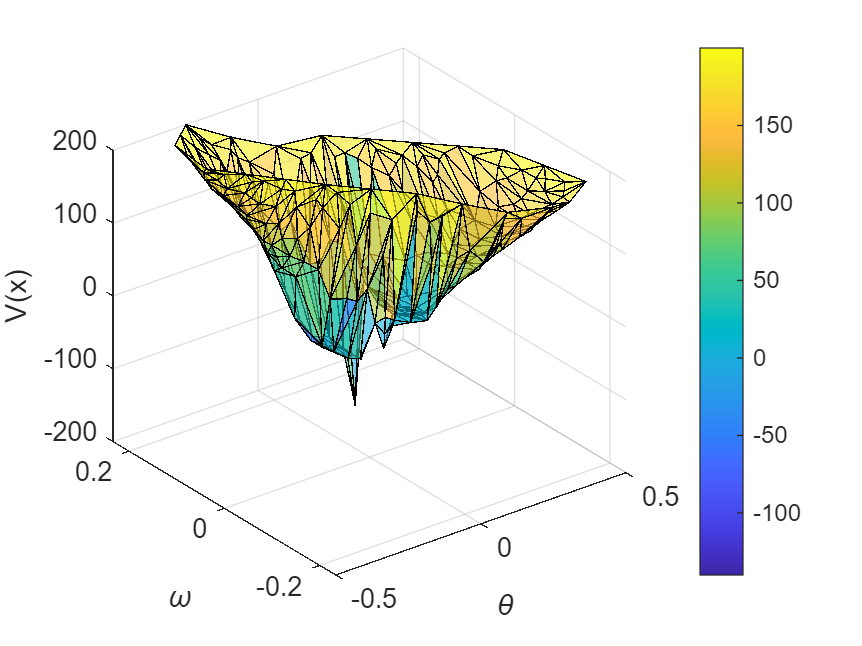

figure
trisurf(C_new2,v_new2(1,:),v_new2(2,:),vals_new2,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new2 bad_triangles_new2 bad_points_new2
bad_ind_new2 = [];
for c = 1:length(ss_new2)
    for i = 1:3
        if ss_new2(i,c) >= 0
            bad_ind_new2 = [bad_ind_new2; [c, i, ss_new2(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

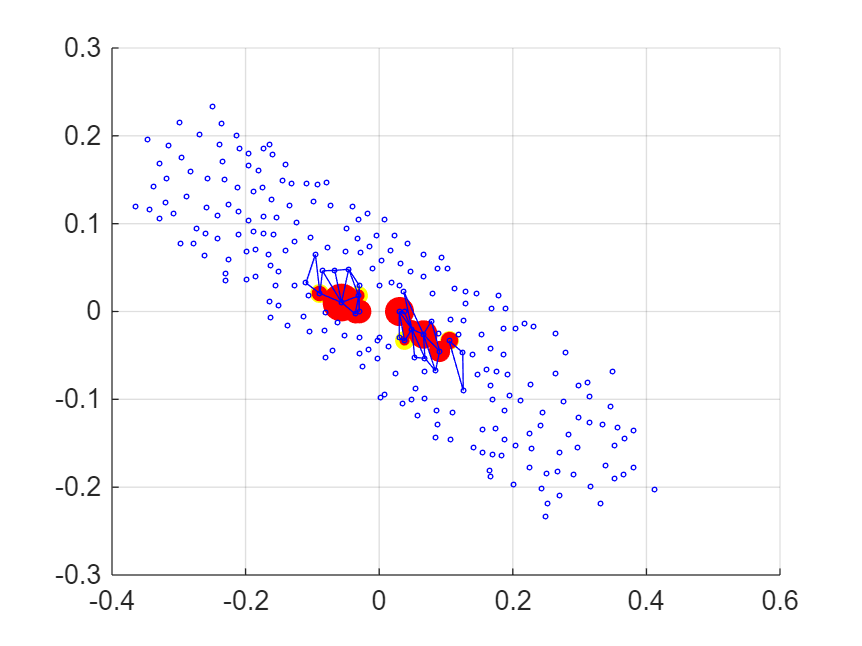

figure
if not(size(bad_ind_new2)==0)
    bad_points_new2 = zeros(2, length(bad_ind_new2(:,1)));
    bad_triangles_new2 = zeros(length(bad_ind_new2(:,1)), 3);
    for ml = 1:length(bad_ind_new2(:,1))
        bad_points_new2(:,ml) = [v_new2(1,C_new2(bad_ind_new2(ml,1),bad_ind_new2(ml,2))); v_new2(2,C_new2(bad_ind_new2(ml,1),bad_ind_new2(ml,2)))]; % points' coordinates
        bad_triangles_new2(ml,:) = C_new2(bad_ind_new2(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new2(1,:), bad_points_new2(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new2(1,:), bad_points_new2(2,:), bad_ind_new2(:,3).*200./max(bad_ind_new2(:,3)), 'r', 'filled')
    triplot(bad_triangles_new2, v_new2(1,:), v_new2(2,:))
end
scatter(v_new2(1,:), v_new2(2,:), 3, 'b')
grid on

[pointlist_new2,a_new2] = sublevelset(dX_new2,C_new2,v_new2,gs_new2,bs_new2,vals_new2,1,[.2 .6 1])

pointlist_new2 =    -0.3352    0.1435
   -0.3305    0.1344
   -0.3278    0.1659
   -0.3217    0.1200
   -0.3177    0.1084
   -0.3157    0.1845
   -0.3133    0.1873
   -0.3039    0.0985
   -0.2968    0.1928
   -0.2927    0.1947


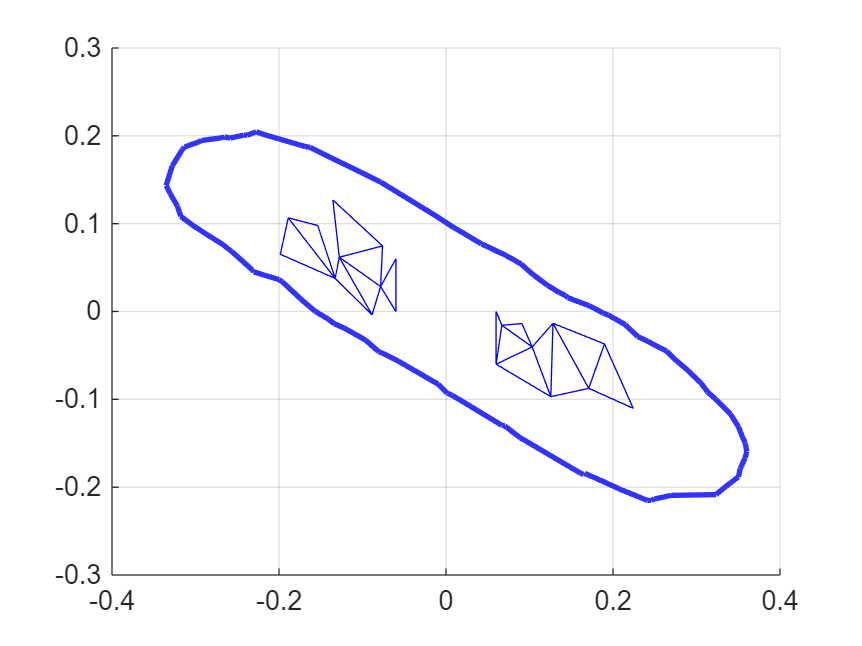

triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
grid on

creating new vertices... 


k = 1.0200

k = 1.0400

k = 1.0600

k = 1.0800

k = 1.1000

k = 1.1200

k = 1.1400

k = 1.1600

k = 1.1800

k = 1.2000

k = 1.2200

k = 1.2400

k = 1.2600

k = 1.2800

k = 1.3000

k = 1.3200

k = 1.3400

k = 1.3600

k = 1.3800

k = 1.4000

k = 1.4200

k = 1.4400

k = 1.4600

k = 1.4800

k = 1.5000

k = 1.5200

k = 1.5400

k = 1.5600

k = 1.5800

k = 1.6000

k = 1.6200

k = 1.6400

k = 1.6600

k = 1.6800

k = 1.7000

k = 1.7200

k = 1.7400

k = 1.7600

k = 1.7800

k = 1.8000

k = 1.8200

k = 1.8400

k = 1.8600

k = 1.8800

k = 1.9000

k = 1.9200

k = 1.9400

k = 1.9600

k = 1.9800

k = 2.0000

k = 2.0200

k = 2.0400

k = 2.0600

k = 2.0800

k = 2.1000

k = 2.1200

k = 2.1400

k = 2.1600

k = 2.1800

k = 2.2000

k = 2.2200

k = 2.2400

k = 2.2600

k = 2.2800

k = 2.3000

k = 2.3200

k = 2.3400

k = 2.3600

k = 2.3800

k = 2.4000

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 50

k = 51

k = 52

k = 53

k = 54

k = 55

k = 56

k = 57

k = 58

k = 59

k = 60

k = 61

k = 62

k = 63

k = 64

k = 65

k = 66

k = 67

k = 68

k = 69

k = 70

k = 71

k = 72

k = 73

k = 74

k = 75

k = 76

k = 77

k = 78

k = 79

k = 80

k = 81

k = 82

k = 83

k = 84

k = 85

k = 86

k = 87

k = 88

k = 89

k = 90

k = 91

k = 92

k = 93

k = 94

k = 95

k = 96

k = 97

k = 98

k = 99

k = 100

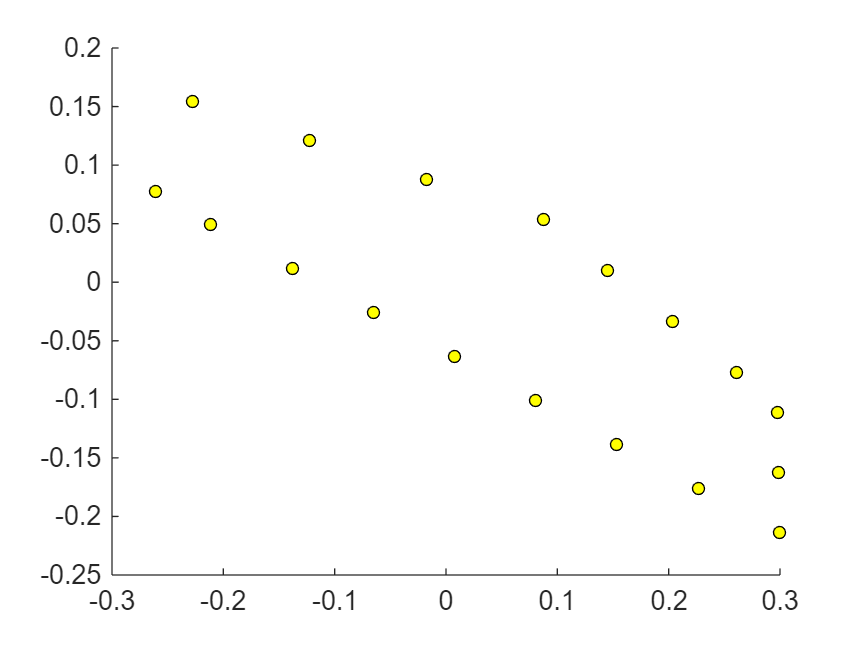

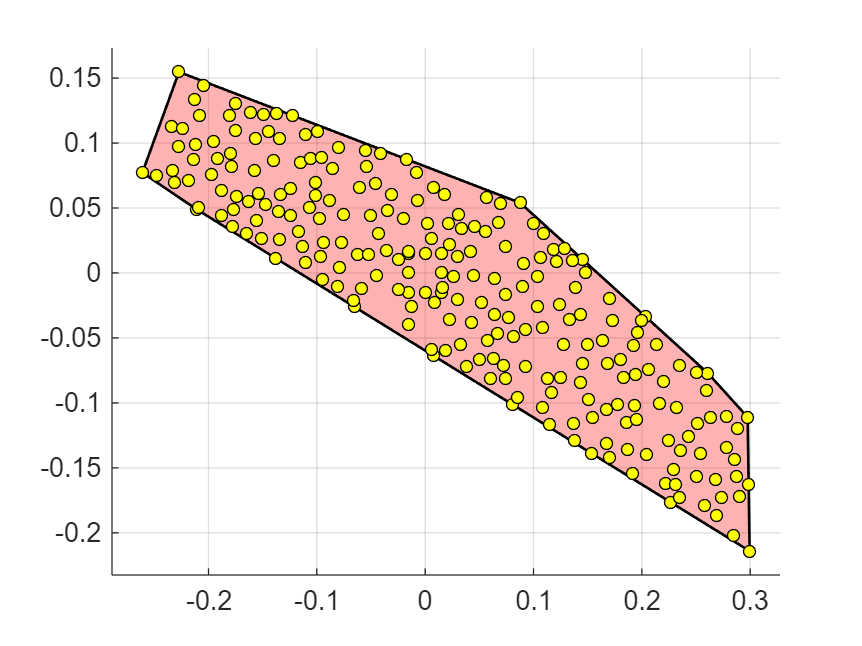

Elapsed time is 0.999293 seconds.
vertices created
 
building the Lyapunov function polyhedron...


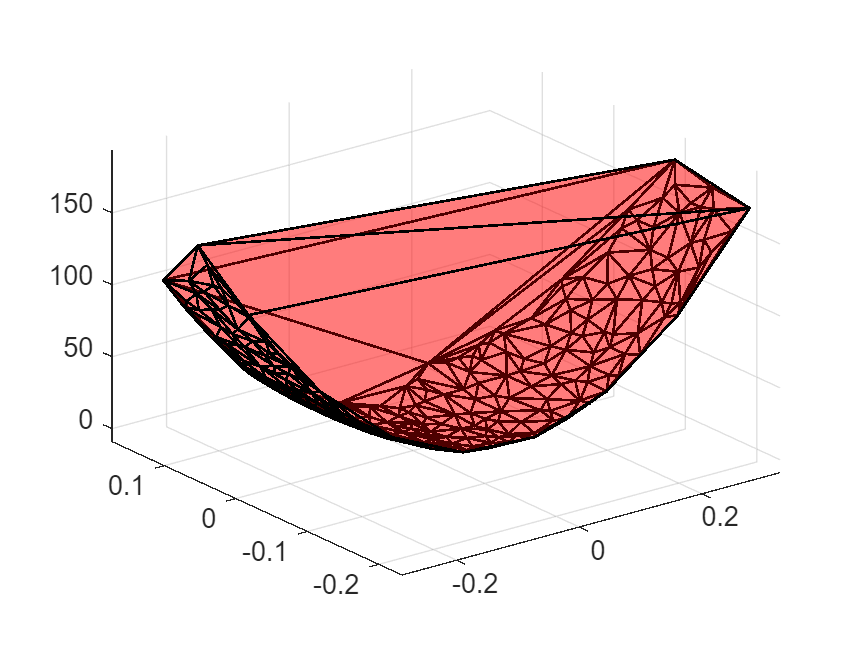

Elapsed time is 4.051756 seconds.
the Lyapunov function polyhedron is built
 
extracting the triangulation...
total loops : 239
5 loops done
10 loops done
15 loops done
20 loops done
25 loops done
30 loops done
35 loops done
40 loops done
45 loops done
50 loops done
55 loops done
60 loops done
65 loops done
70 loops done
75 loops done
80 loops done
85 loops done
90 loops done
95 loops done
100 loops done
105 loops done
110 loops done
115 loops done
120 loops done
125 loops done
130 loops done
135 loops done
140 loops done
145 loops done
150 loops done
155 loops done
160 loops done
165 loops done
170 loops done
175 loops done
180 loops done
185 loops done
190 loops done
195 loops done
200 loops done
205 loops done
210 loops done
215 loops done
220 loops done
225 loops done
230 loops done
235 loops done
Elapsed time is 1623.337742 seconds.
triangulation extracted
 
plotting the resulting polyhedra...
Elapsed time is 50.620755 seconds.
polyhedra construction and plot ended
 
cleaning the 

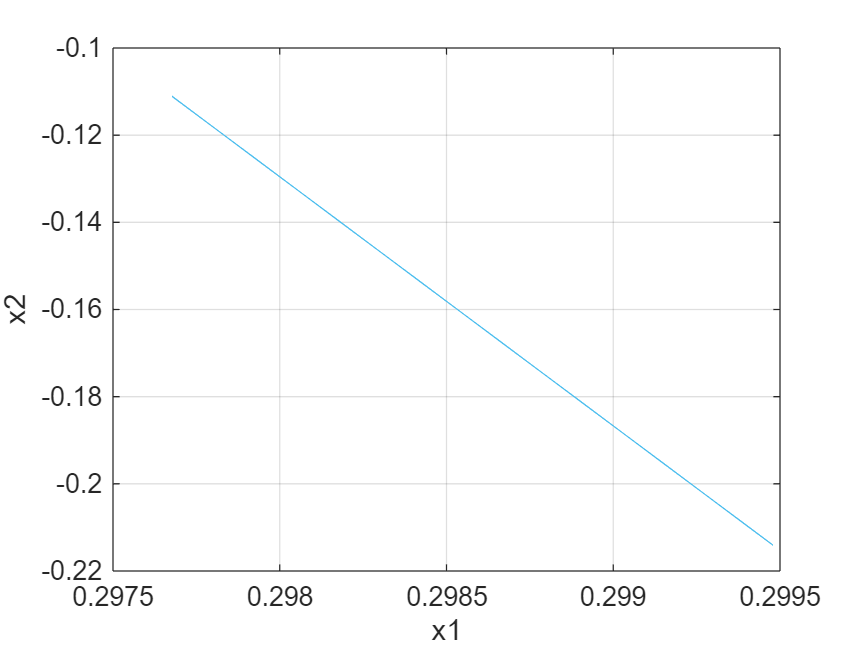

Elapsed time is 0.428056 seconds.
constraint verification ended
 


[v_new3,C_new3,Nv_new3,Nc_new3,dX_new3,Tess_new3,extind_new3] = TessellationFinderV2(270,v_new2,bad_triangles_new2,0.15*l_A,'random',pointlist_new2,0.015);

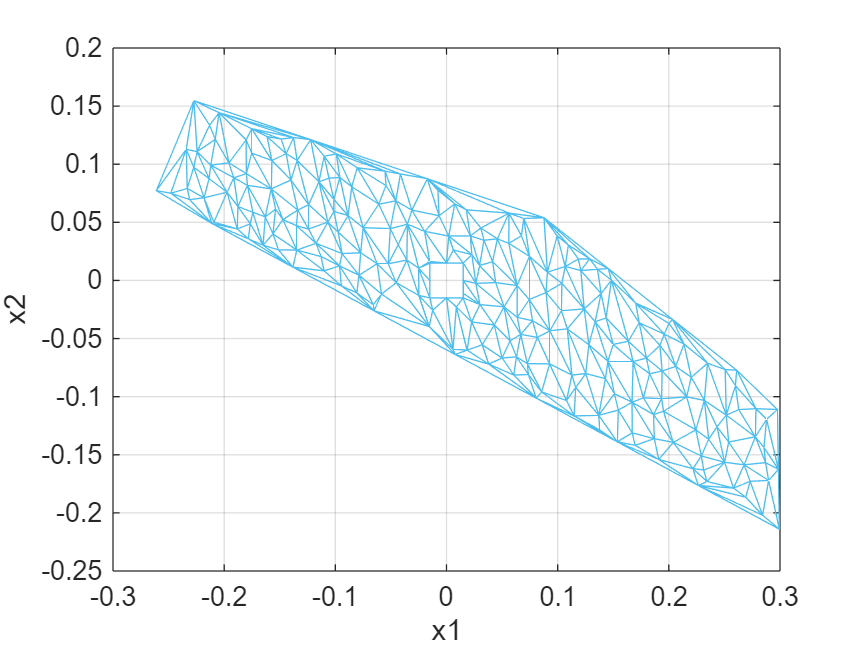

figure
triplot(C_new3, v_new3(1,:), v_new3(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

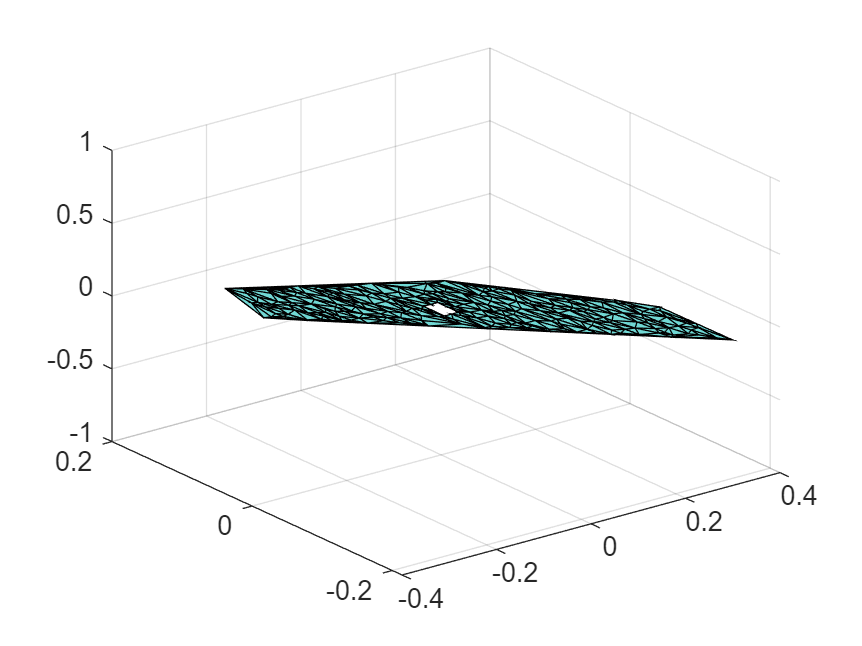

figure
trisurf(C_new3,v_new3(1,:),v_new3(2,:),zeros(length(v_new3),1),'FaceAlpha',.6)
grid on

l_new3 = [min(v_new3(1,:)),max(v_new3(1,:));min(v_new3(2,:)),max(v_new3(2,:))];
[x_new3,f_new3,Nd_new3] = DataGenerator(370,rt,l_new3,v_new3,Tess_new3,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

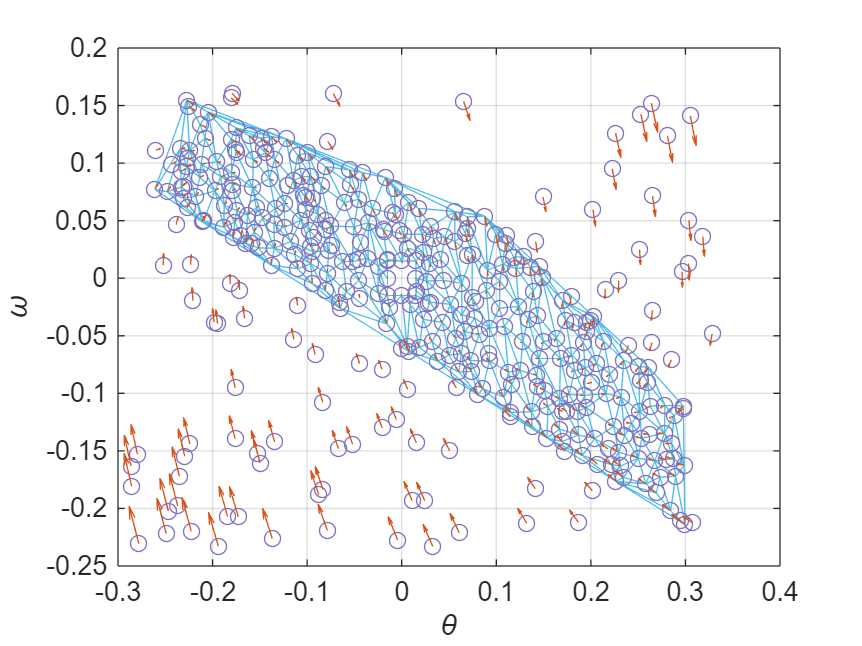

figure
triplot(C_new3, v_new3(1,:), v_new3(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new3(1,:), x_new3(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new3(1,:), x_new3(2,:), f_new3(1,:), f_new3(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new3 bs_new3 vals_new3 ss_new3 sum_ss_new3
[gs_new3,bs_new3,vals_new3,ss_new3,sum_ss_new3] = OptimisationProblem(x_new3,f_new3,M,v_new3,C_new3,eps,eta,alpha,beta,dA,dX_new3,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 452
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 1.1829e+04
       solvertime: 129.8753
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 12174.945629 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new3)*3)

Computed optimal value : -6780.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new3)

Obtained optimal value : -6460.073719


fprintf('Error : %f\n', sum_ss_new3 + eta*length(C_new3)*3)

Error : 319.926281


We plot the solution in 3D, each triangle is plotted independently from the others.

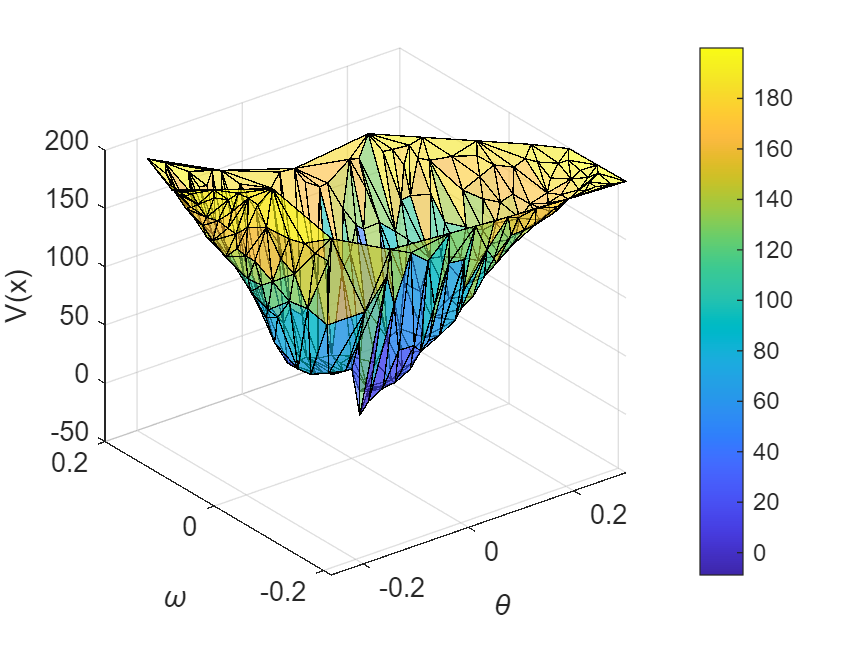

figure
trisurf(C_new3,v_new3(1,:),v_new3(2,:),vals_new3,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new3 bad_triangles_new3 bad_points_new3
bad_ind_new3 = [];
for c = 1:length(ss_new3)
    for i = 1:3
        if ss_new3(i,c) >= 0
            bad_ind_new3 = [bad_ind_new3; [c, i, ss_new3(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

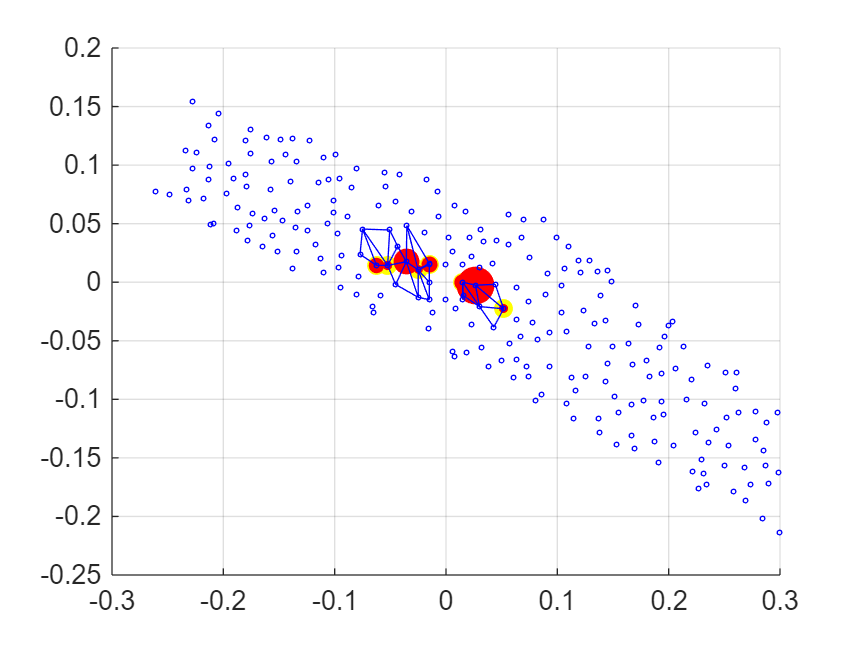

figure
if not(size(bad_ind_new3)==0)
    bad_points_new3 = zeros(2, length(bad_ind_new3(:,1)));
    bad_triangles_new3 = zeros(length(bad_ind_new3(:,1)), 3);
    for ml = 1:length(bad_ind_new3(:,1))
        bad_points_new3(:,ml) = [v_new3(1,C_new3(bad_ind_new3(ml,1),bad_ind_new3(ml,2))); v_new3(2,C_new3(bad_ind_new3(ml,1),bad_ind_new3(ml,2)))]; % points' coordinates
        bad_triangles_new3(ml,:) = C_new3(bad_ind_new3(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new3(1,:), bad_points_new3(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new3(1,:), bad_points_new3(2,:), bad_ind_new3(:,3).*200./max(bad_ind_new3(:,3)), 'r', 'filled')
    triplot(bad_triangles_new3, v_new3(1,:), v_new3(2,:))
end
scatter(v_new3(1,:), v_new3(2,:), 3, 'b')
grid on

[pointlist_new3,a_new3] = sublevelset(dX_new3,C_new3,v_new3,gs_new3,bs_new3,vals_new3,1,[.2 .6 1])

pointlist_new3 =    -0.1827    0.0934
   -0.1826    0.0911
   -0.1822    0.0835
   -0.1803    0.0793
   -0.1801    0.0947
   -0.1783    0.0981
   -0.1781    0.0772
   -0.1742    0.0736
   -0.1715    0.1030
   -0.1675    0.1069


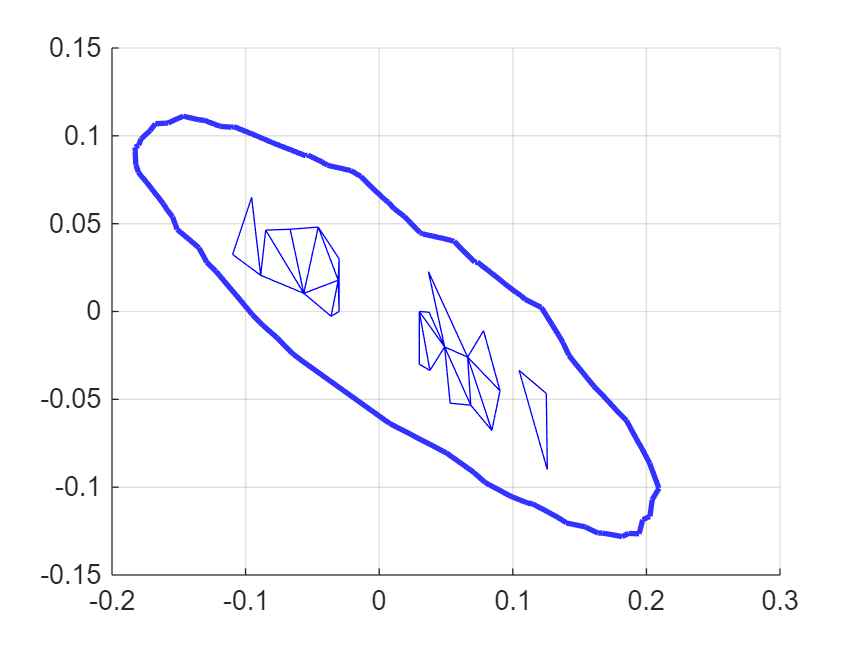

triplot(bad_triangles_new2, v_new2(1,:), v_new2(2,:))
grid on